cd(fileparts(matlab.desktop.editor.getActiveFilename))
pwd

ans = '/Users/ellarond/Dropbox/Papers/Neural plate fate choice/v3.0/Code'

addpath("utils")
plot_dir = fullfile('..', 'Plots');
if ~isfolder(plot_dir)
    mkdir(plot_dir);
end


CELL_SIZE = 5;
GRID_RES = 2; %number of cell_size within one grid element
bs = CELL_SIZE*GRID_RES; 

gene_ids = {'1D2', '1J', '1Q', '2C', '2G', '2H', '2K', '3F', '3I', '3J', '3M', '3P', '4D', '4I', '4J', '4M', '4R', '4S'};
gene_names = {'foxb1b', 'neurog1', 'her6', 'her9', 'nkx6.1', 'pax6b', 'zic2a', 'her3', 'olig2', 'prdm8a', 'pax3a', 'dbx1b', 'her15.1', ...
    'nkx6.2', 'olig4', 'zic2b', 'prdm12b', 'irx3a'};


map_dir = fullfile('TF_maps');
%[mapavg_fns, mapavg_fn_path] = uigetfile('*.mat', "MultiSelect", "on");


atlas_sox19 = []; 
atlas_nptf = []; 
std_nptf = [];

for k = 1:length(gene_ids) %length(mapavg_fns)
    temp = load(fullfile(map_dir, [gene_ids{k}, '_map_avg.mat']));
    %temp = load(fullfile(mapavg_fn_path, mapavg_fns{k}));
    map_avg = temp.map_avg;
    %gene_names{end + 1} = temp.map_avg.gene_name;
    atlas_sox19 = cat(3, atlas_sox19, map_avg.channel2.reg_mean_map);
    atlas_nptf = cat(3, atlas_nptf, map_avg.channel3.reg_mean_map);
    num_samples = 3; %length(fieldnames(temp.map_avg.channel1)) - 2;
    spx_sample_maps = [];
    for sn = 1:num_samples
        spx_smap = create_superpixels(temp.map_avg.channel3.(['sample', num2str(sn)]), [], bs);
        spx_sample_maps = cat(3, spx_sample_maps, spx_smap);
    end
    
    % downsampled std deviation
    % std_nptf = cat(3, std_nptf, std(spx_sample_maps, [], 3));
        
    % full resolution std deviation
    std_nptf = cat(3, std_nptf, map_avg.channel3.std_map);
end

mean_sox19 = mean(atlas_sox19, 3);
sox19_mask = 0*mean_sox19;
sox19_mask(mean_sox19 > 0.2) = 1;
props = regionprops(sox19_mask, 'BoundingBox');
bb = uint8(props.BoundingBox);

masked_atlas_nptf = bsxfun(@times, atlas_nptf, sox19_mask);

masked_std_nptf = [];
masked_std_nptf = bsxfun(@times, std_nptf, sox19_mask);

sox19_mask_stack = repmat(sox19_mask, 1, 1, size(masked_atlas_nptf, 3));

TRUNC_ROW_START = 131;
TRUNC_ROW_END = 580;
clipped_nptf = masked_atlas_nptf;
clipped_nptf(sox19_mask_stack == 0) = nan;
clipped_nptf = clipped_nptf(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(clipped_nptf, 2)/2, :);
nptf_superpix = [];

clipped_std = masked_std_nptf;
clipped_std = clipped_std(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(clipped_std, 2)/2, :);
std_superpix = [];

s = size(clipped_nptf);

clipped_sox19 = mean_sox19(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(mean_sox19, 2)/2, :);
spx_sox19 = create_superpixels(clipped_sox19, [], bs);

spx_by_gene = zeros((s(1)/bs)*(s(2)/bs), s(3));
std_by_gene = zeros((s(1)/bs)*(s(2)/bs), s(3));


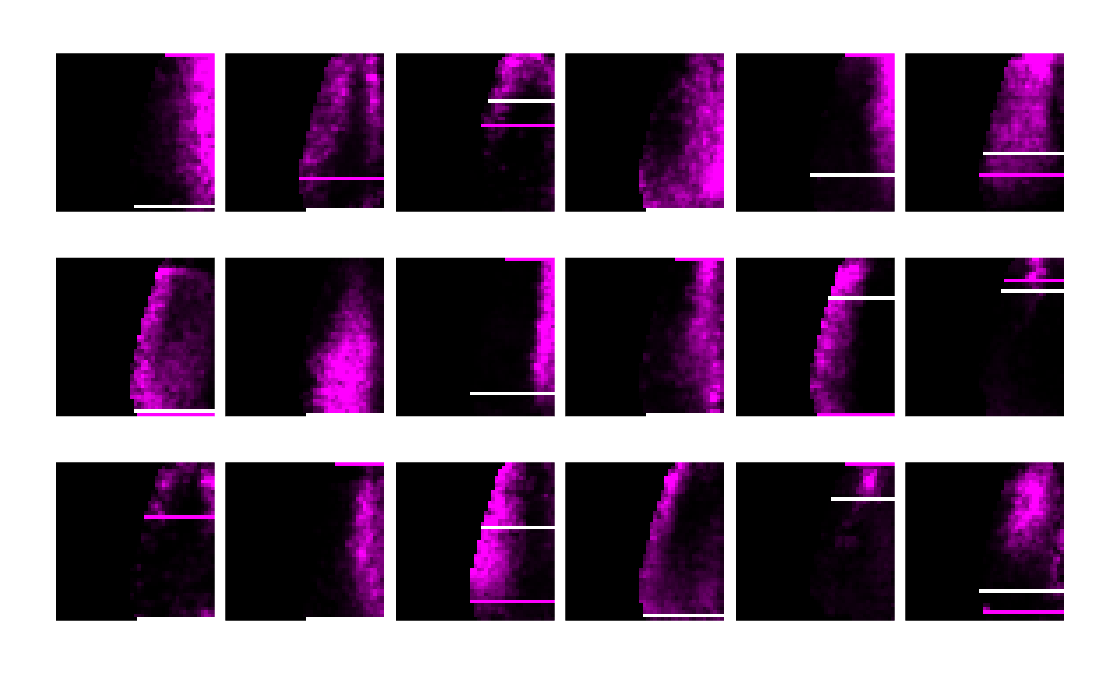

ap_pos_by_gene = zeros(length(gene_ids), 2);
ap_exp_thres = 0.2;
clipped_nptf_spx = [];
f = figure; 
for gn = 1:size(clipped_nptf, 3)
    %spx_map = create_superpixels(clipped_nptf(:, :, gn), [], bs);
    [spx_map, spx_std] = create_superpixels(clipped_nptf(:, :, gn), clipped_std(:, :, gn), bs);

    %spx_map = medfilt2(spx_map, [3 3]);
   

    lm_cutoff = 10; 
    if ~isempty(find(max(spx_map(:, 1:end-lm_cutoff), [], 2) > ap_exp_thres, 1, 'last'))
        ap_pos_by_gene(gn, 1) = find(max(spx_map(:, 1:end-lm_cutoff), [], 2) > ap_exp_thres, 1, 'last');
    end

    if ~isempty(find(max(spx_map(:, end - lm_cutoff:end), [], 2) > ap_exp_thres, 1, 'last'))
        ap_pos_by_gene(gn, 2) = find(max(spx_map(:, end - lm_cutoff:end), [], 2) > ap_exp_thres, 1, 'last');
    end
    
    %ap_pos_by_gene(gn) = find(mean(spx_map, 2, 'omitnan') > ap_exp_thres, 1, 'last');
    lat_im = 0*spx_map; med_im = 0*spx_map;
    lat_im(max([ap_pos_by_gene(gn, 1), 1]), :) = 1;
    med_im(max([ap_pos_by_gene(gn, 2), 1]), :) = 1;

    % if std map created from superpixelated version
    %spx_std = std_nptf(:, :, gn);
    %spx_std = spx_std(:, 1:size(spx_std, 2)/2);

    % build superpixel by gene matrix
    spx_by_gene(:, gn) = reshape(spx_map, [], 1);
    std_by_gene(:, gn) = reshape(spx_std, [], 1);

    nptf_superpix = cat(3, nptf_superpix, spx_map);
    std_superpix = cat(3, std_superpix, spx_std);
    subtightplot(3, 6, gn); 
    rgb_im = cat(3, 2*spx_map + lat_im + med_im, 0*spx_map + med_im, 2*spx_map + lat_im + med_im);
    imshow(rgb_im)
    %imshow(masked_atlas_nptf(:, :, gn), []);
end
saveas(f, fullfile(plot_dir, 'superpixelated_maps_with_ap.svg'));

nan_values = 0*spx_by_gene;
nan_values(isnan(spx_by_gene)) = 1;
valid_rows = find(~ismember(nan_values, ones(1, size(nan_values, 2)), 'rows'));
spx_by_gene = spx_by_gene(valid_rows, :);
std_by_gene = std_by_gene(valid_rows, :);

[r, c] = ind2sub(size(spx_map), valid_rows);
spx_pos = [r, c];

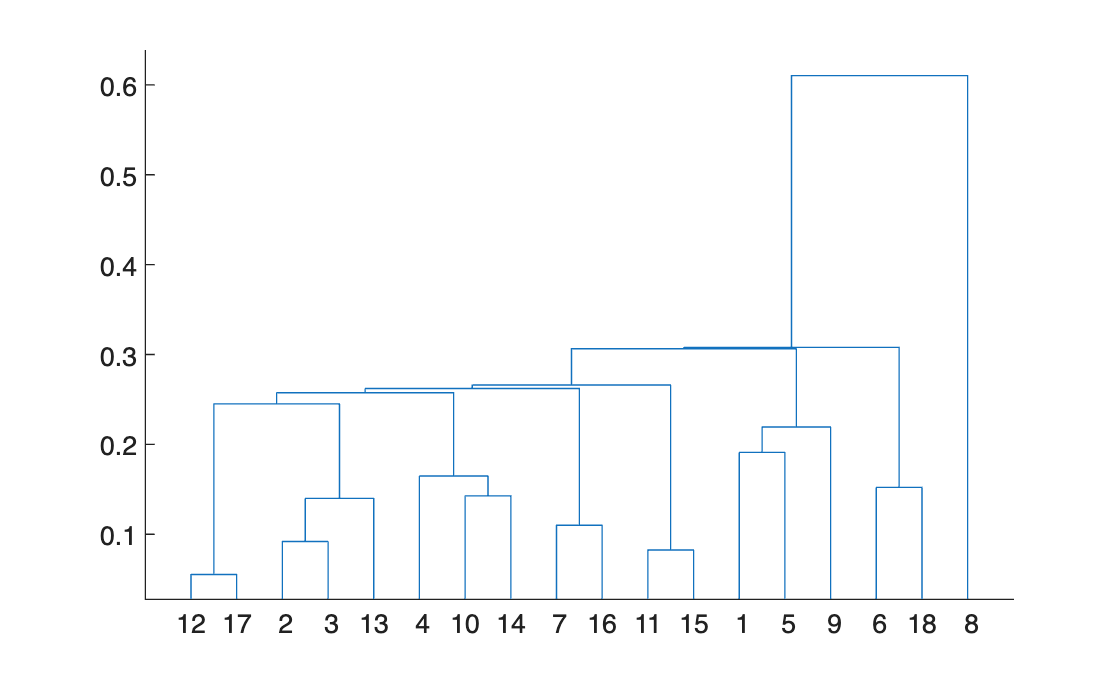

% PCA
f1 = figure;
[coeff, score, ~, ~, explained] = pca(spx_by_gene);

comp_colormap = zeros(100, 3);
for r = 1:50
    comp_colormap(r, :) = [(50 - r)/50, 0, (50 - r)/50];
end
for r = 51:100
    comp_colormap(r, :) = [(r - 50)/50, (r - 50)/50, 0];
end
colormap(comp_colormap)

subplot(2, 2, 1); 
%colormap(hot)
imagesc(coeff, [-0.6 0.6]);
xticks([1, 5, 10, 15]);
xlabel('Principal component')
yticks(1:length(gene_names)); yticklabels(gene_names); colorbar();
subplot(2, 2, 2); 
plot(0:size(spx_by_gene, 2), [0, cumsum(explained)'], 'bo-'); ylabel('Percent variability explained'); xticks(0:5:18); xlim([0 18]); xlabel('Principal component')

subplot(2, 2, 3);
[gene_names_az, sort_order] = sort(gene_names);

imagesc(coeff(sort_order, :)', [-0.6 0.6]);
yticks([1, 5, 10, 15]);
ylabel('Principal component')
xticks(1:length(gene_names)); xticklabels(gene_names_az); colorbar();


rng('default');
comp_links = linkage(pdist(coeff(:, 1:3)));
f2 = figure;
[~, ~, pca_gene_order] = dendrogram(comp_links);

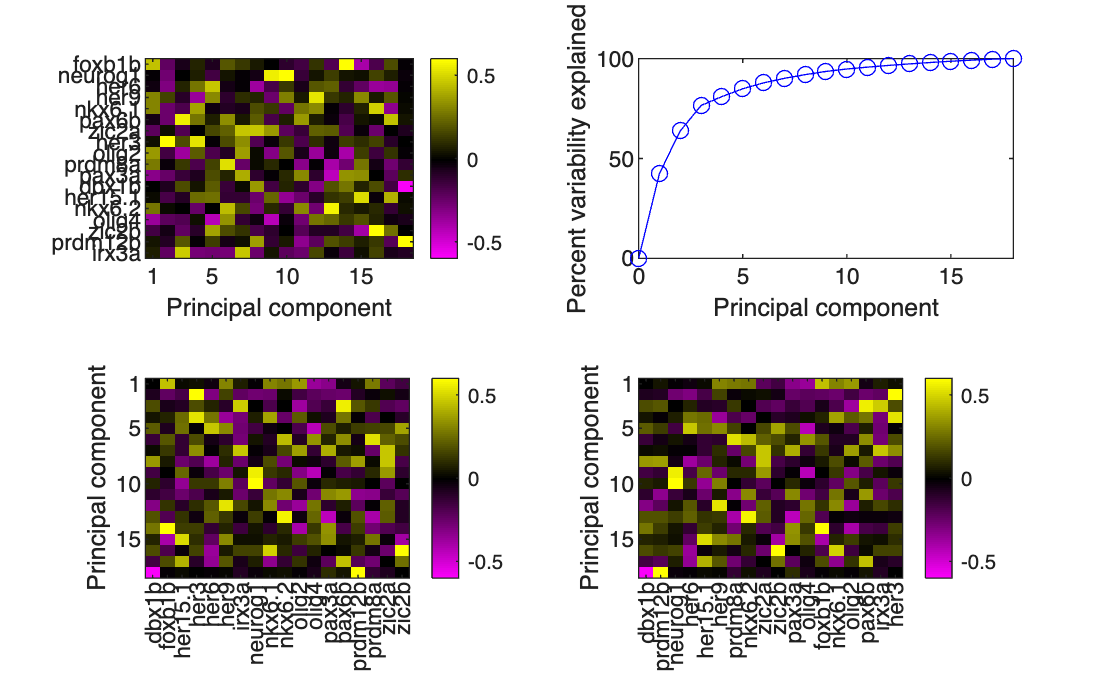


figure(f1)
subplot(2, 2, 4);
imagesc(coeff(pca_gene_order, :)', [-0.6 0.6]);
yticks([1, 5, 10, 15]);
ylabel('Principal component')
xticks(1:length(gene_names)); xticklabels(gene_names(pca_gene_order)); colorbar();
saveas(f1, fullfile(plot_dir, 'PCA_components.svg'))



%subplot(2, 2, 2); biplot(coeff(:, [1, 2]),'scores',score(:, [1, 2]),'varlabels', gene_names);
%subplot(2, 2, 3); biplot(coeff(:, [1, 3]),'scores',score(:, [1, 3]),'varlabels', gene_names);
%subplot(2, 2, 4); biplot(coeff(:, [2, 3]),'scores',score(:, [2, 3]),'varlabels', gene_names);

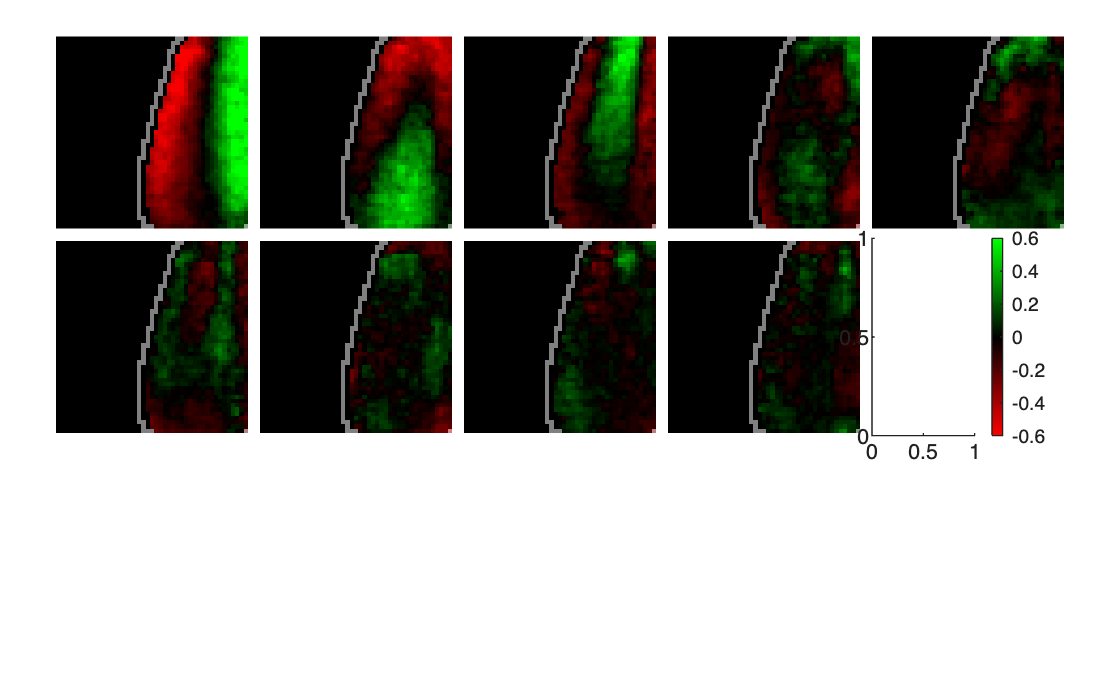

f2 = figure; 
pca_colormap = zeros(100, 3);
for r = 1:50
    pca_colormap(r, :) = [(50 - r)/50, 0, 0];
end
for r = 51:100
    pca_colormap(r, :) = [0, (r - 50)/50, 0];
end
colormap(pca_colormap)

% sox19 outline
filtered_im = imfilter(spx_sox19, fspecial('average', 5));
spx_sox19_mask = logical(mat2gray(filtered_im, [0.1 0.6]));
np_outline = imdilate(spx_sox19_mask, strel('square', 3)) - spx_sox19_mask;
%np_outline = imdilate(logical(spx_sox19), strel('square', 3)) - logical(spx_sox19);

%imshow(np_outline)

for comp = 1:9
    subtightplot(3, 5, comp); 
    temp = ones(size(spx_map))/2;
    for p = 1:size(spx_pos, 1)
        temp(spx_pos(p, 1), spx_pos(p, 2)) = (score(p, comp) + 1)/2;
    end
    rgb_temp = ind2rgb(gray2ind(mat2gray(temp, [0.2 0.8]), size(pca_colormap, 1)), pca_colormap);
   
    for ch = 1:3
        rgb_temp(:, :, ch) = rgb_temp(:, :, ch) + np_outline/2;
    end
    
    imshow(rgb_temp); 
    xticks(''); yticks('')
end
subtightplot(3, 5, 10); 
c = colorbar();
c.Ticks = 0:(1/6):1;
c.TickLabels = string(-0.6:0.2:0.6);

%saveas(f2, fullfile(plot_dir, 'pca_modes.svg'));


% for comp = 1:10
%     subtightplot(2, 5, comp); 
%     temp_r = 0*spx_map; temp_g = 0*spx_map;
%     for p = 1:size(spx_pos, 1)
%         if score(p, comp) > 0 
%             temp_g(spx_pos(p, 1), spx_pos(p, 2)) = score(p, comp);
%         else            
%             temp_r(spx_pos(p, 1), spx_pos(p, 2)) = -1*score(p, comp);
%         end
%     end
%     imshow(cat(3, temp_r, temp_g, 0*temp_g));
% end

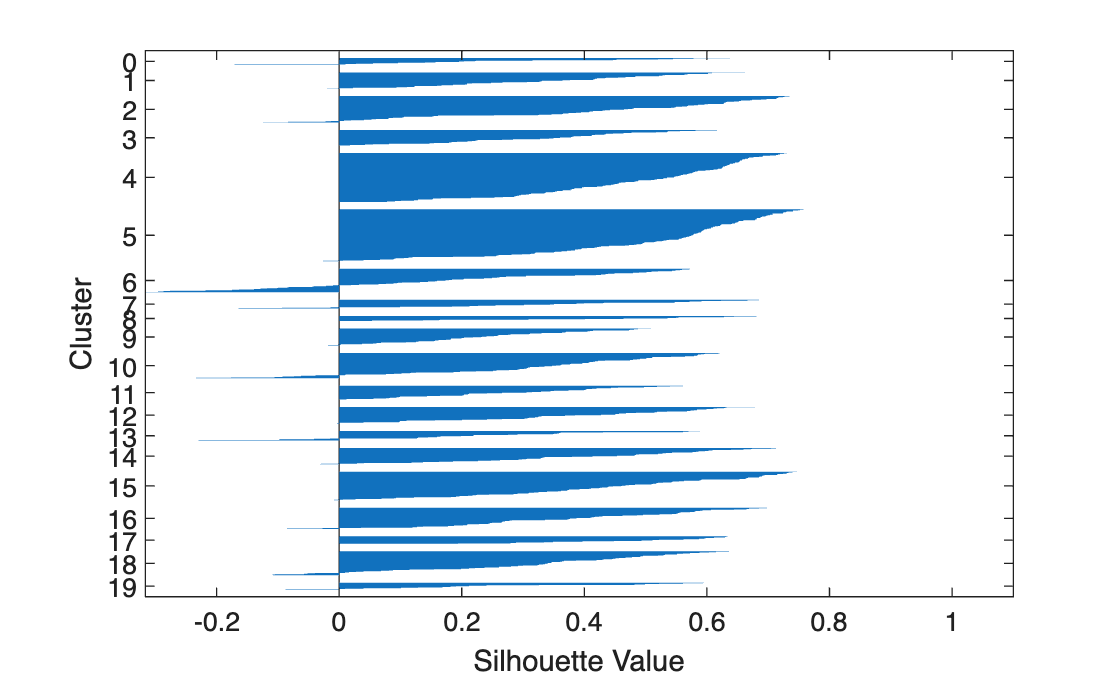

f = figure;
tot_clusters = 20;
s_values = zeros(1, tot_clusters);
gene_max_mean = zeros(length(gene_names), tot_clusters);
gene_min_mean = zeros(length(gene_names), tot_clusters);
% alternative clustering
for k = 1:tot_clusters
    num_clusters  = k;
    rng('default');
    clusterIdentifiers = kmeans(spx_by_gene, num_clusters) - 1;
    [s, h] = silhouette(spx_by_gene, clusterIdentifiers);
    s_values(k) = sum(s);

    gene_means_k = zeros(length(gene_names), k);    
    for i = 1:k
        idx = find(clusterIdentifiers == i - 1);
        gene_means_k(:, i) = mean(spx_by_gene(idx, :), 1)';
    end
    gene_max_mean(:, k) = max(gene_means_k, [], 2);
    gene_min_mean(:, k) = min(gene_means_k, [], 2);

end

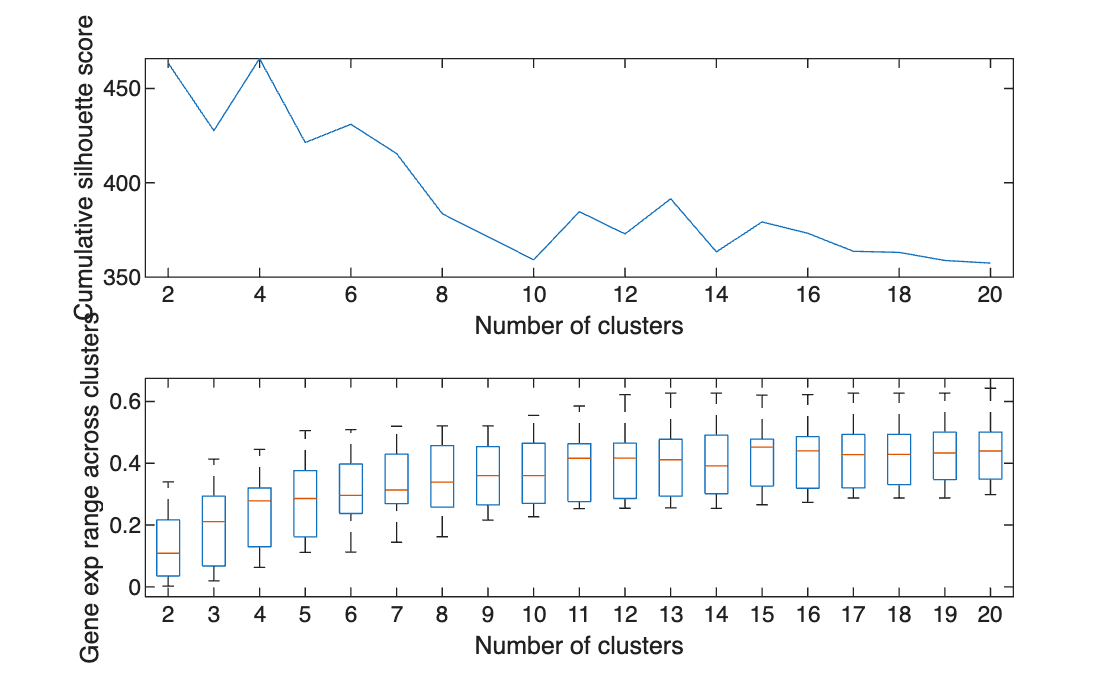

f = figure; 
subplot(2, 1, 1); plot(1:tot_clusters, s_values); xlim([1.5, 20.5])
ylabel('Cumulative silhouette score'); xlabel('Number of clusters');
subplot(2, 1, 2); boxplot(gene_max_mean - gene_min_mean); xlim([1.5, 20.5])
ylabel('Gene exp range across clusters'); xlabel('Number of clusters');
saveas(f, fullfile(plot_dir, 'silhoutte_v_diversity.svg'))

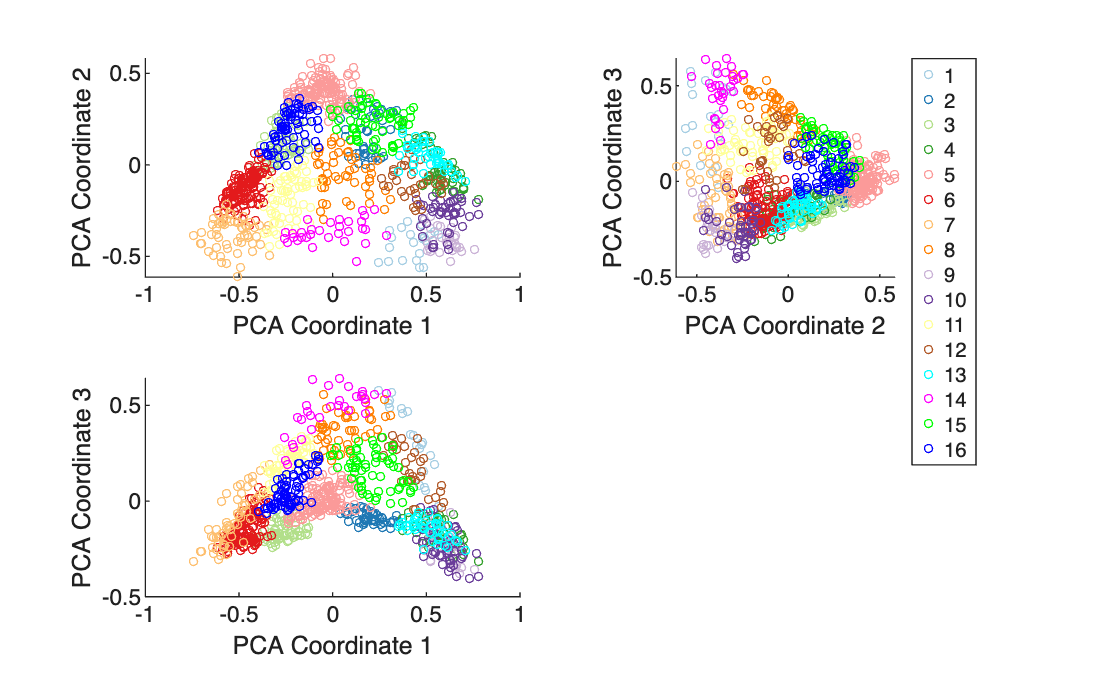

num_clusters = 16;  
cluster_colors = cbrewer2('Paired', 12);
cluster_colors = cat(1, cluster_colors, [0 1 1; 1 0 1; 0 1 0; 0 0 1]);
%rand_seed = rng('shuffle');
%cluster_colors = cluster_colors(randperm(num_clusters), :);

rng('default');
clusterIdentifiers = kmeans(spx_by_gene, num_clusters) - 1;
f1 = figure; 


cluster_labels = unique(clusterIdentifiers);
for cn = 1:length(cluster_labels)
   subplot(2, 2, 1); hold on;
%    plot3(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 2), ...
%       score(clusterIdentifiers == cluster_labels(cn), 3), 'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :));
    plot(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 2), ...
        'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
    xlabel('PCA Coordinate 1');
    ylabel('PCA Coordinate 2');

     subplot(2, 2, 3); hold on;
     plot(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 3), ...
         'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
     xlabel('PCA Coordinate 1');
     ylabel('PCA Coordinate 3');

     subplot(2, 2, 2); hold on;
     plot(score(clusterIdentifiers == cluster_labels(cn), 2), score(clusterIdentifiers == cluster_labels(cn), 3), ...
         'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
     xlabel('PCA Coordinate 2');
     ylabel('PCA Coordinate 3');


end
axis square
legend(string(cluster_labels + 1), 'Location', 'eastoutside');

saveas(f1, fullfile(plot_dir, 'pca_plot.svg'))

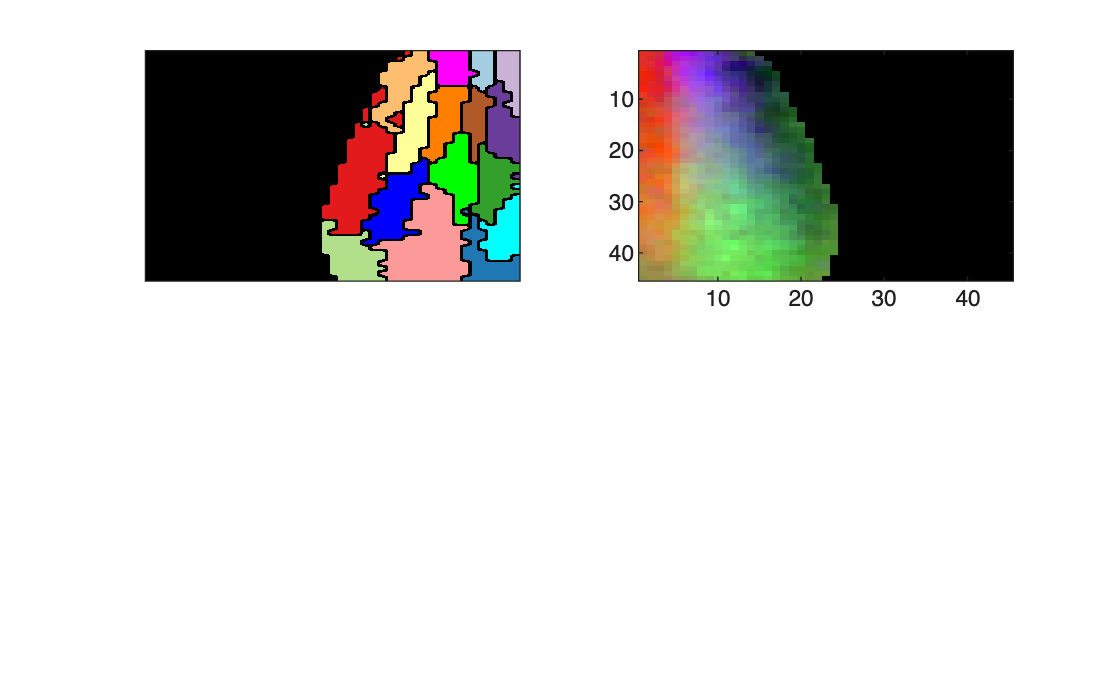

%saveas(f1, fullfile(plot_dir, 'pca_plot_w_silhouette.svg'));

f1 = figure;
cluster_map = zeros(size(spx_map));
cluster_map_rgb = repmat(0*spx_map, 1, 1, 3);
pca_pos_map = repmat(0*spx_map, 1, 1, 3);   
pca_xmin = min(score(:, 1)); pca_xmax = max(score(:, 1));
pca_ymin = min(score(:, 2)); pca_ymax = max(score(:, 2));
pca_zmin = min(score(:, 3)); pca_zmax = max(score(:, 3));

for p = 1:size(spx_pos, 1)
    px_color = cluster_colors(find(cluster_labels == clusterIdentifiers(p)), :);
    cluster_map(spx_pos(p, 1), spx_pos(p, 2)) = clusterIdentifiers(p) + 1;
    cluster_map_rgb(spx_pos(p, 1), spx_pos(p, 2), :) = px_color; 
    pca_pos_map(spx_pos(p, 1), spx_pos(p, 2), :) = [(score(p, 1) - pca_xmin)/(pca_xmax - pca_xmin), (score(p, 2) - pca_ymin)/(pca_ymax - pca_ymin), (score(p, 3) - pca_zmin)/(pca_zmax - pca_zmin)];
end

outlined_cluster_map_rgb =  zeros(5*size(cluster_map, 1), 5*size(cluster_map, 2), 3); %0*cluster_map_rgb; %
%rsz_cluster_map = imresize(cluster_map, 2);
for cn = 1:num_clusters
    temp = 0*cluster_map;
    temp(cluster_map == cn) = 1;
    temp = imresize(logical(temp), 5);
    temp_erode = imerode(temp, strel('square', 3));
    %temp_erode = temp - temp_erode; %imerode(temp_erode, strel('square', 3));
    cc = cluster_colors(cn, :);
    outlined_cluster_map_rgb = outlined_cluster_map_rgb + cat(3, cc(1)*temp_erode, cc(2)*temp_erode, cc(3)*temp_erode);
end


subplot(2, 2, 1); 
imagesc(outlined_cluster_map_rgb);
xticks(''); yticks('');
subplot(2, 2, 2); imagesc(pca_pos_map(:, end:-1:1, :));
saveas(f1, fullfile(plot_dir, 'cluster_map_rgb.svg'))

## Cluster markers

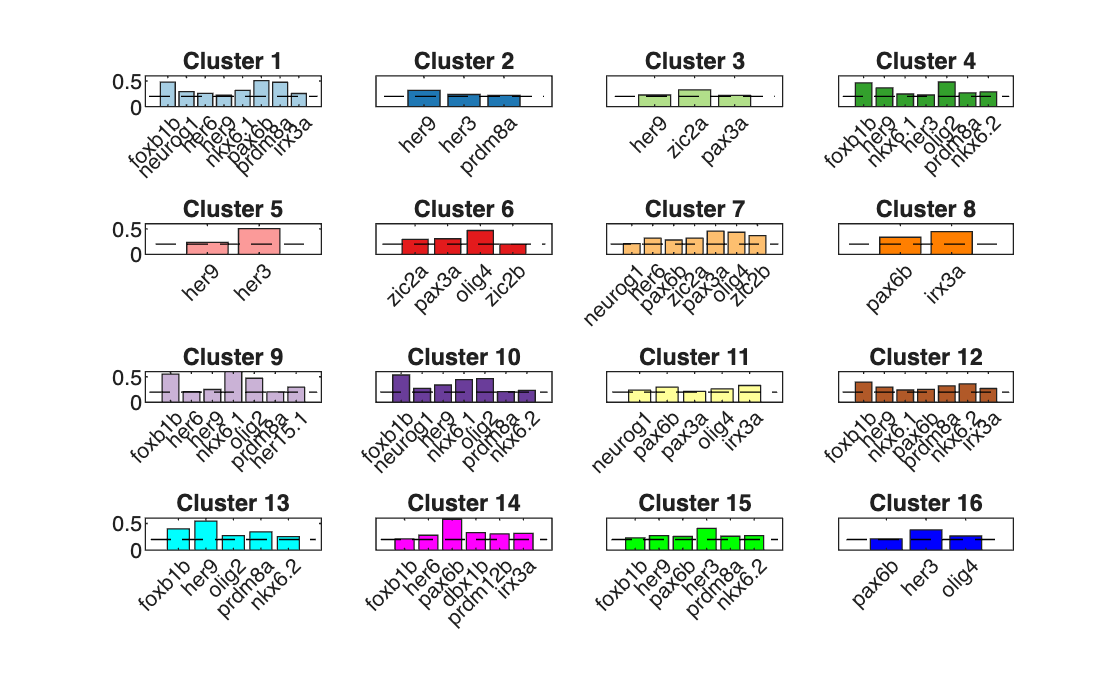

props = regionprops(cluster_map, {'Centroid', 'PixelList'});
centroids = cat(1, props.Centroid);
[sorted_centroids, sort_order] = sortrows(fliplr(centroids));
props = props(sort_order);
label_grid = reshape(sort_order, 4, [])';
new_label_grid = 0*label_grid;

for r = 1:size(label_grid, 1) 
    [~, order] = sortrows(fliplr(centroids(label_grid(r, :), :)), 2);
    new_label_grid(r, :) = label_grid(r, order);
end

f2 = figure;
exp_thres = 0.2;
gene_x_cluster_matrix = [];
for cn = 1:length(cluster_labels)
    if cn <= 4
        subplot(4, 4, cn);
    elseif cn >= 16
        subplot(4, 4, mod(cn, 4) + 16);
    elseif cn >= 12
        subplot(4, 4, mod(cn, 4) + 12);
    elseif cn >= 8
        subplot(4, 4, mod(cn, 4) + 8);
    else
        subplot(4, 4, mod(cn, 4) + 4);
    end
    mean_vals_by_gene = mean(spx_by_gene(clusterIdentifiers == cluster_labels(cn), :));
    gene_x_cluster_matrix(end + 1, :) = mean_vals_by_gene;
    exp_gene_idx = find(mean_vals_by_gene > exp_thres);
    b = bar(mean_vals_by_gene(exp_gene_idx));
    b.FaceColor = cluster_colors(cn, :);
    %hold on;
    %errorbar(1:length(gene_names), mean(spx_by_gene(clusterIdentifiers == cluster_labels(cn), :)), mean(std_by_gene(clusterIdentifiers == cluster_labels(cn), :)), 'LineStyle', 'none')
    xticks(1:length(exp_gene_idx))
    xticklabels(gene_names(exp_gene_idx));
    xtickangle(45)
    ylim([0 0.6]);
    if mod(cn, 4) ~=1
        yticks('')
    end
    line([0 length(gene_names(exp_gene_idx)) + 1], [exp_thres exp_thres], 'LineStyle', '--', 'Color', 'black')
    title(['Cluster ', num2str(cn)])
end
saveas(f2, fullfile(plot_dir, ['cluster_genemarkers_thres', num2str(exp_thres), '.svg']))

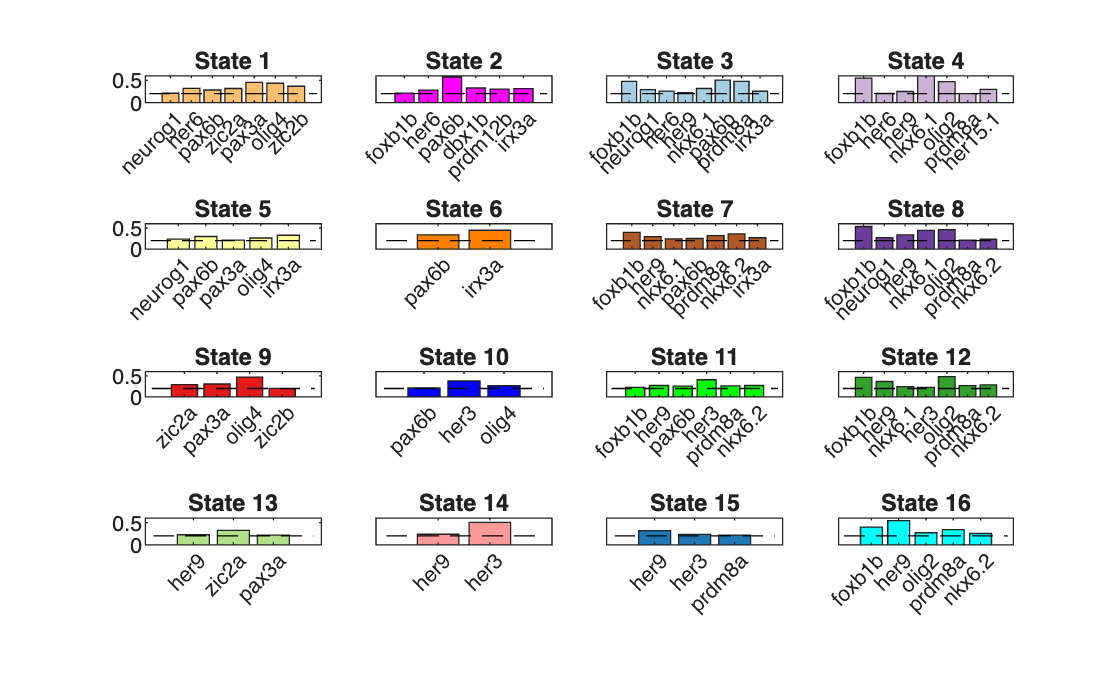

f3 = figure;
i = 1;
for r = 1:4
    for c = 1:4
        subplot(4, 4, i);
        cn = new_label_grid(r, c);
        exp_gene_idx = find(gene_x_cluster_matrix(cn, :) > exp_thres);
        b = bar(gene_x_cluster_matrix(cn, exp_gene_idx));
        b.FaceColor = cluster_colors(cn, :);
        xticks(1:length(exp_gene_idx))
        xticklabels(gene_names(exp_gene_idx));
        xtickangle(45)
        ylim([0 0.6]);
        if mod(i, 4) ~=1
            yticks('')
        end
        line([0 length(gene_names(exp_gene_idx)) + 1], [exp_thres exp_thres], 'LineStyle', '--', 'Color', 'black')
        title(['State ', num2str(i)])    
        i = i + 1;
    end
end
saveas(f3, fullfile(plot_dir, 'cluster_genemarkers_APML_ordered.svg'))

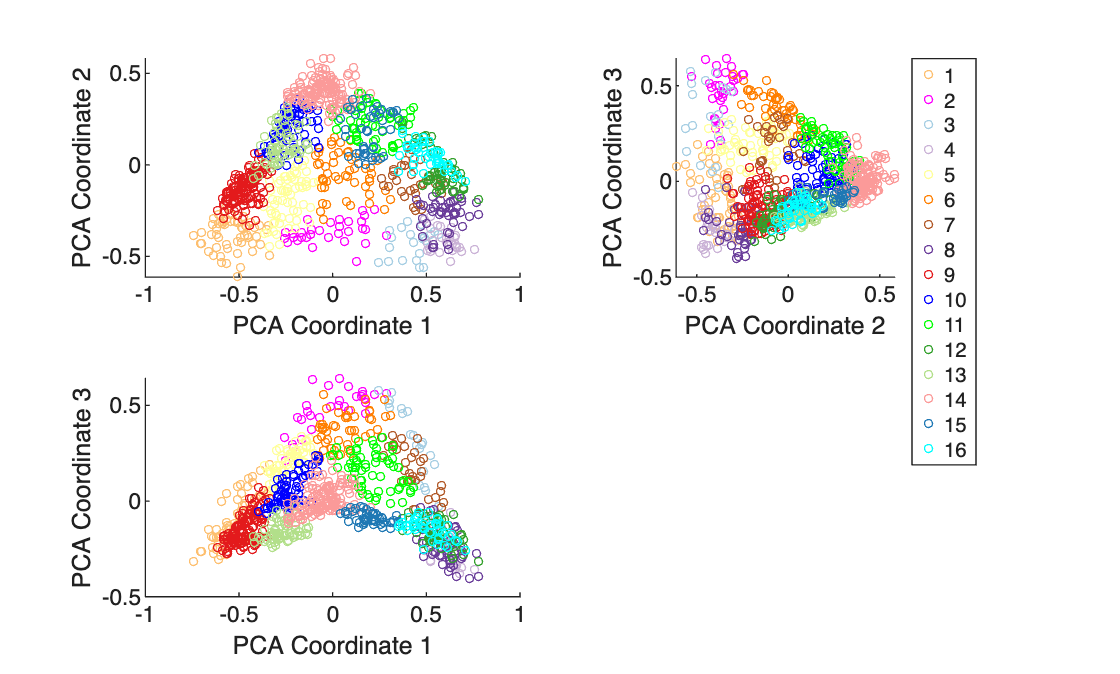

f = figure;
i = 1;
for r = 1:4
    for c = 1:4
        cn = new_label_grid(r, c);
       subplot(2, 2, 1); hold on;
        plot(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 2), ...
            'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
        xlabel('PCA Coordinate 1');
        ylabel('PCA Coordinate 2');
    
         subplot(2, 2, 3); hold on;
         plot(score(clusterIdentifiers == cluster_labels(cn), 1), score(clusterIdentifiers == cluster_labels(cn), 3), ...
             'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
         xlabel('PCA Coordinate 1');
         ylabel('PCA Coordinate 3');
    
         subplot(2, 2, 2); hold on;
         plot(score(clusterIdentifiers == cluster_labels(cn), 2), score(clusterIdentifiers == cluster_labels(cn), 3), ...
             'Marker', 'o', 'LineStyle', 'none', 'Color', cluster_colors(cn, :), 'MarkerSize', 3);
         xlabel('PCA Coordinate 2');
         ylabel('PCA Coordinate 3');
    end
end
axis square
legend(string(cluster_labels + 1), 'Location', 'eastoutside');

saveas(f, fullfile(plot_dir, 'pca_plot_APML_ordering.svg'))

## Cluster relatedness

neighbor_matrix = zeros(num_clusters, num_clusters);
%find neighbors
for c1 = 1:num_clusters
    for c2 = c1:num_clusters

        temp1 = 0*cluster_map; temp2 = 0*cluster_map; temp_merge = 0*cluster_map;
        temp1(cluster_map == c1) = 1;
        temp1 = imopen(temp1, strel(3));
        temp_merge(cluster_map == c1) = 1;
        temp2(cluster_map == c2) = 1;
        temp2 = imopen(temp2, strel(3));
        temp_merge(cluster_map == c2) = 1;
        temp_merge = imopen(temp_merge, strel(3));
        if max(nonzeros(bwlabel(temp_merge))) < max(nonzeros(bwlabel(temp1))) + max(nonzeros(bwlabel(temp2)))
            neighbor_matrix(c1, c2) = 1;
        end
    end
end


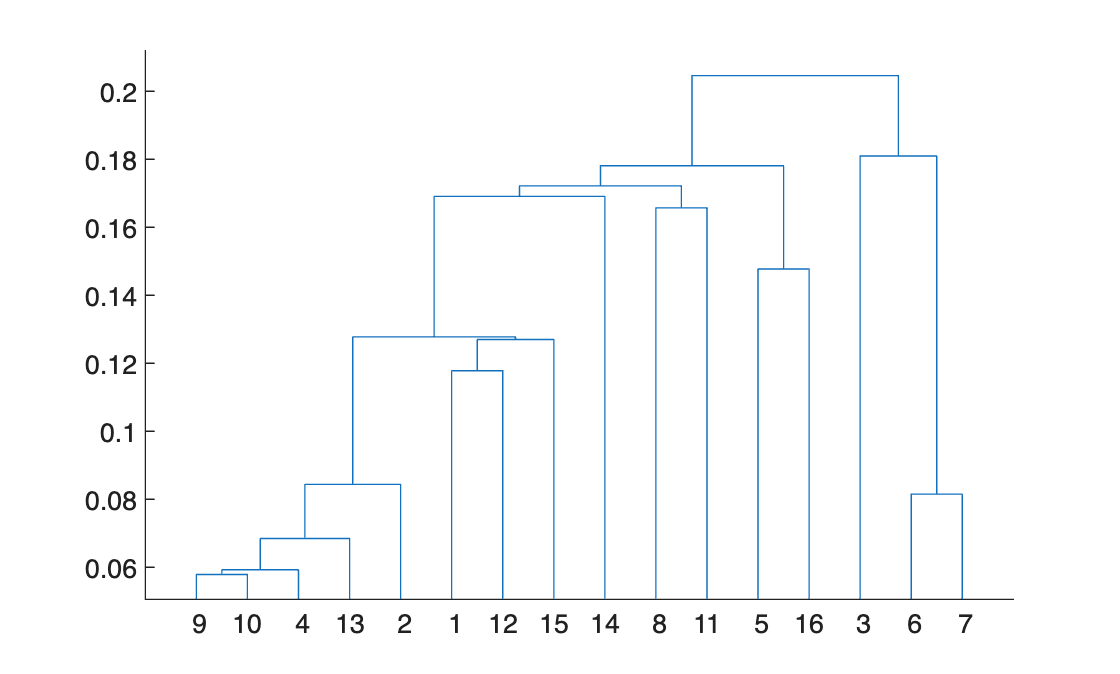

figure;
%imshow(cat(3, gene_x_cluster_matrix, 0*gene_x_cluster_matrix, gene_x_cluster_matrix))
%imagesc(gene_x_cluster_matrix)
filt_gene_x_cluster_matrix = gene_x_cluster_matrix;
%filt_gene_x_cluster_matrix(gene_x_cluster_matrix < 0.1) = 0;
rng('default');
clust_dist = pdist(filt_gene_x_cluster_matrix, 'cosine');
clust_links = linkage(clust_dist);
[~, ~, cluster_order] = dendrogram(clust_links);

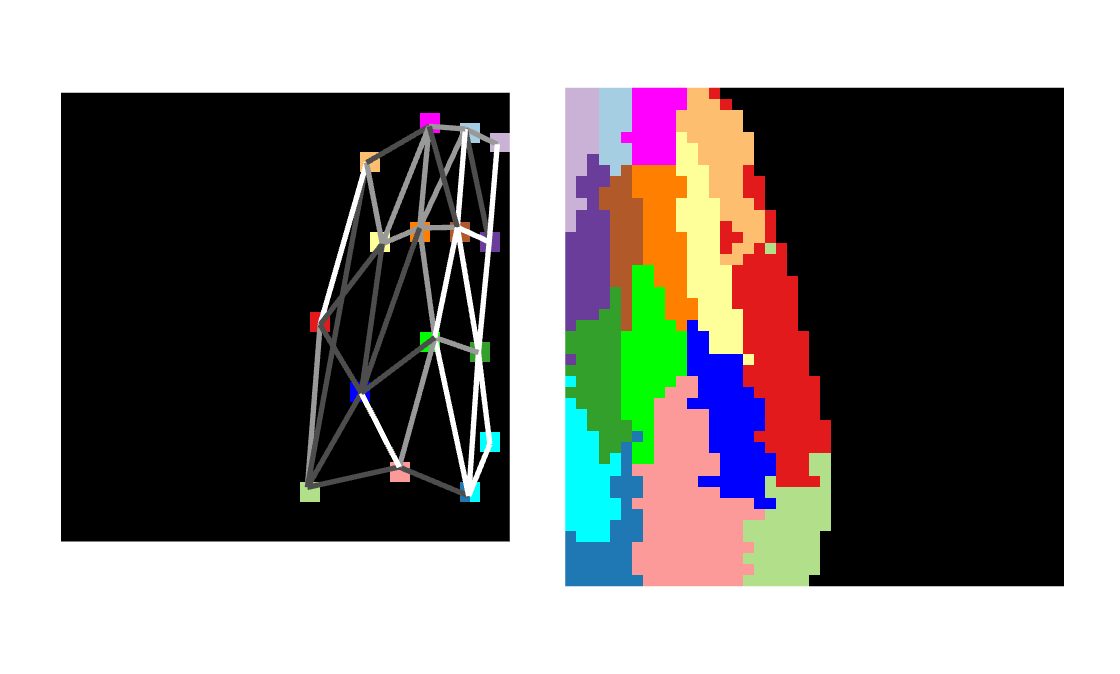

f = figure; 
subtightplot(1, 2, 2); 
imshow(cluster_map_rgb(:, end:-1:1, :)); 
subtightplot(1, 2, 1); hold on;
cluster_spot_map = 0*cluster_map_rgb;
spot_size = 0.5;
for c = 1:size(centroids, 1)
    rows = uint8((centroids(c, 2) - spot_size):min((centroids(c, 2) + spot_size), size(cluster_map, 1)));
    cols = uint8((centroids(c, 1) - spot_size):min((centroids(c, 1) + spot_size), size(cluster_map, 2)));
    cluster_spot_map(rows, cols, :) = cluster_map_rgb(rows, cols, :);
end
imshow(cluster_spot_map);

props = regionprops(cluster_map, 'Area', 'Centroid');
centroids = reshape([props.Centroid], 2, num_clusters)';

clust_dist_full = squareform(clust_dist);
filt_clust_dist_full = clust_dist_full.*neighbor_matrix;
weak = prctile(nonzeros(filt_clust_dist_full), 33);
med = prctile(nonzeros(filt_clust_dist_full), 66);

line_colors = [0.3 0.3 0.3; 0.6 0.6 0.6; 1 1 1];
for i = 1:size(centroids, 1)
    for j = i:size(centroids, 1)
        if filt_clust_dist_full(i, j) > 0
            if filt_clust_dist_full(i, j) < weak
                line([centroids(i, 1), centroids(j, 1)], ...
                    [centroids(i, 2), centroids(j, 2)], 'LineWidth', 2, 'Color',  line_colors(3, :)); %0.3*(1/clust_dist_full(i, j))
            elseif filt_clust_dist_full(i, j) < med
                line([centroids(i, 1), centroids(j, 1)], ...
                    [centroids(i, 2), centroids(j, 2)], 'LineWidth', 2, 'Color',  line_colors(2, :));
            else
                line([centroids(i, 1), centroids(j, 1)], ...
                    [centroids(i, 2), centroids(j, 2)], 'LineWidth', 2, 'Color',  line_colors(1, :));
            end
        end

    end
end
saveas(f, fullfile(plot_dir, 'cluster_relatedness_graph.svg'));

## Relationship to signaling

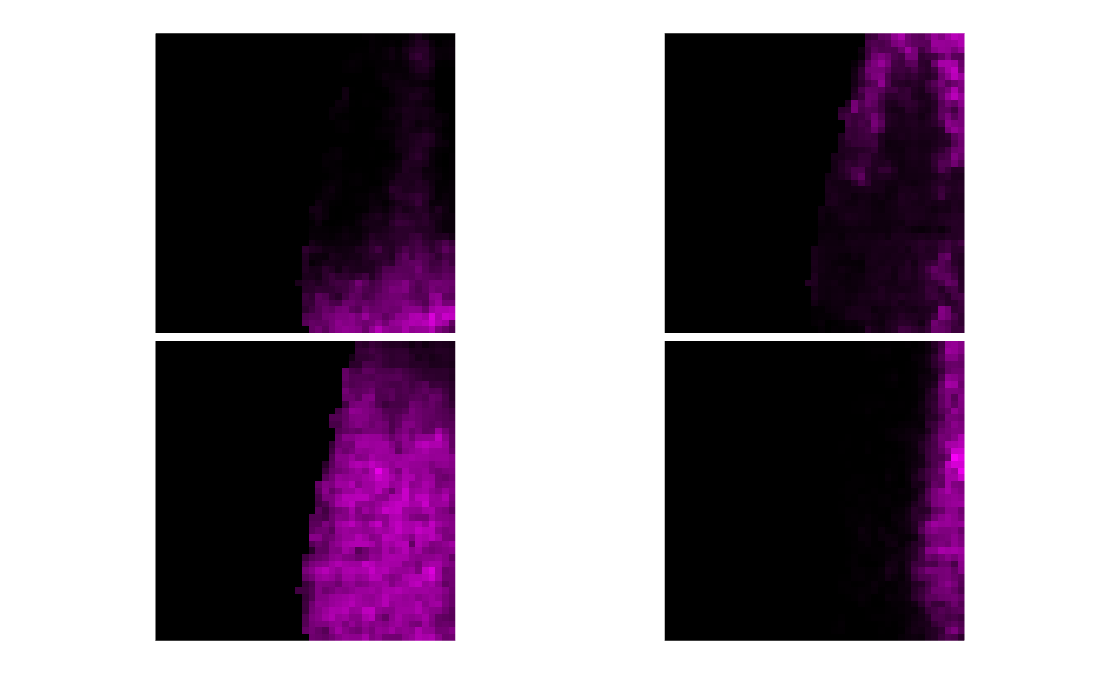

signal_dir = 'Signal_maps';
signal_ids = {'1P', '4N', 'pERK', 'Ptch2'};

signal_channels = [3, 3, 4, 3];
signal_sox19_channels = [2, 2, 2, 2];
    
atlas_signals = []; 
atlas_signals_sox19 = []; 

for k = 1:length(signal_ids) 
    temp = load(fullfile(signal_dir, [signal_ids{k}, '_map_avg.mat']));
    map_avg = temp.map_avg;
    if isfield(map_avg.channel1, 'reg_mean_map')
        atlas_signals_sox19 = cat(3, atlas_signals_sox19, map_avg.(['channel', num2str(signal_sox19_channels(k))]).reg_mean_map);
        atlas_signals = cat(3, atlas_signals, map_avg.(['channel', num2str(signal_channels(k))]).reg_mean_map);
    else
        atlas_signals_sox19 = cat(3, atlas_signals_sox19, map_avg.(['channel', num2str(signal_sox19_channels(k))]).mean_map);
        atlas_signals = cat(3, atlas_signals, map_avg.(['channel', num2str(signal_channels(k))]).mean_map);
    end
end

mean_signals_sox19 = mean(atlas_signals_sox19, 3);
sox19_mask = 0*mean_signals_sox19;
sox19_mask(mean_signals_sox19 > 0.2) = 1;

masked_atlas_signals = bsxfun(@times, atlas_signals, sox19_mask);
sox19_mask_stack = repmat(sox19_mask, 1, 1, size(masked_atlas_signals, 3));

clipped_signals = masked_atlas_signals;
clipped_signals(sox19_mask_stack == 0) = nan;
clipped_signals = clipped_signals(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(clipped_signals, 2)/2, :);
signals_superpix = [];

s = size(clipped_signals);

clipped_sox19 = mean_sox19(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(mean_sox19, 2)/2, :);
spx_sox19 = create_superpixels(clipped_sox19, [], bs);

spx_by_signal = zeros((s(1)/bs)*(s(2)/bs), s(3));
clipped_signals_spx = [];
f = figure; hold on;
for sn = 1:size(clipped_signals, 3)
    [spx_map, spx_std] = create_superpixels(clipped_signals(:, :, sn), 0*clipped_signals(:, :, sn), bs);

    % build superpixel by gene matrix
    spx_by_signal(:, gn) = reshape(spx_map, [], 1);

    signals_superpix = cat(3, signals_superpix, spx_map);
    subtightplot(2, 2, sn); 
    rgb_im = cat(3, spx_map, 0*spx_map, spx_map);
    imshow(rgb_im)
    %imshow(masked_atlas_nptf(:, :, gn), []);
end

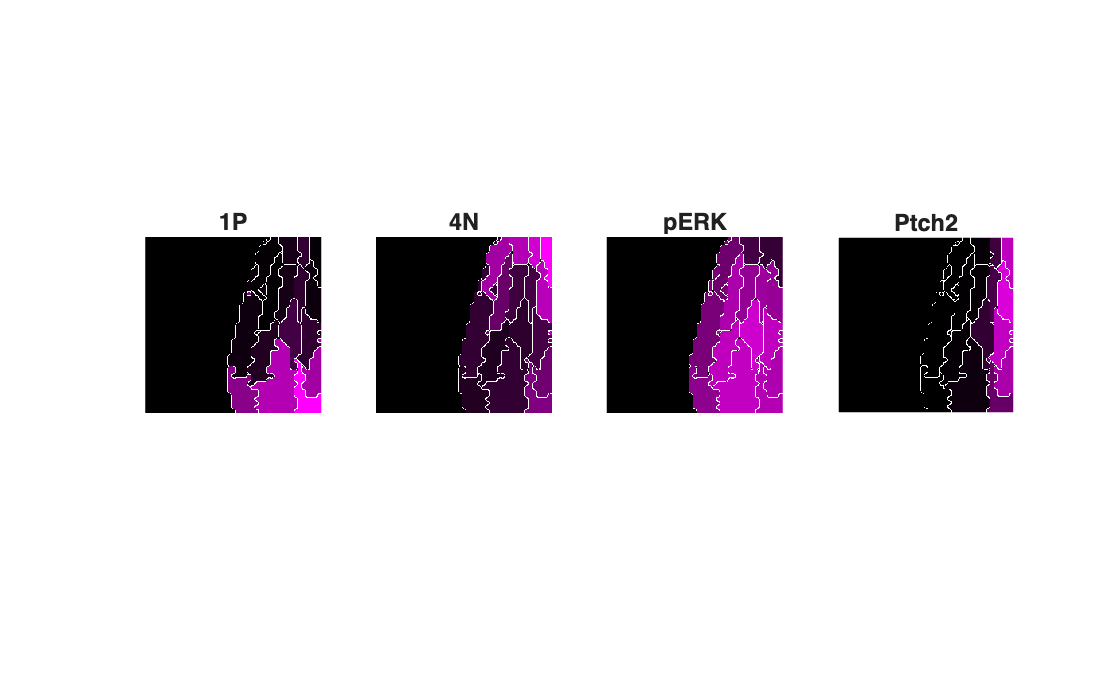


f2 = figure;
signal_lims = [0 0.5; 0.05 0.5; 0.2 0.5; 0.1 0.5];
mean_multiplier = [2, 2, 1.26, 1.5];
for sn = 1:length(signal_ids)

    signal_map = squeeze(atlas_signals(:, :, sn));
    signal_map = signal_map(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(signal_map, 2)/2);
    mean_map = 0*signal_map;
    outline_map = 0*signal_map;
    for cn = 1:num_clusters    
        temp = 0*cluster_map;
        temp(cluster_map == cn) = 1 ; %mean(signal_spx_map(cluster_map == cn), 'omitnan');
        temp = imresize(logical(temp), 10);
        temp_erode = double(imerode(temp, strel('square', 3)));

        outline_map((temp - temp_erode) == 1) = 1; %overlay_map(temp_erode == 1) + signal_map(temp_erode == 0);
        %outline_map = imdilate(outline_map, strel('square', 2));
        temp_erode(temp_erode == 1) = nonzeros(mean(signal_map(temp_erode == 1)))*mean_multiplier(sn);
        mean_map = mean_map + cat(3, temp_erode + outline_map, 0*temp_erode + outline_map, temp_erode + outline_map);
    end
    signal_map(outline_map == 1) = 1;
    f1 = figure; %subplot(1, 4, sn); 
    imshow(cat(3, mat2gray(signal_map, signal_lims(sn, :)), outline_map, mat2gray(signal_map, signal_lims(sn, :))))
    title(signal_ids{sn});
    saveas(f1, fullfile(plot_dir, ['cluster_overlay_on_signals_', num2str(sn), '.svg']));
    close(f1);

    figure(f2); subplot(1, 4, sn); 
    imshow(mean_map)
    title(signal_ids{sn});
    
end

saveas(f2, fullfile(plot_dir, 'mean_signal_in_clusters.svg'));

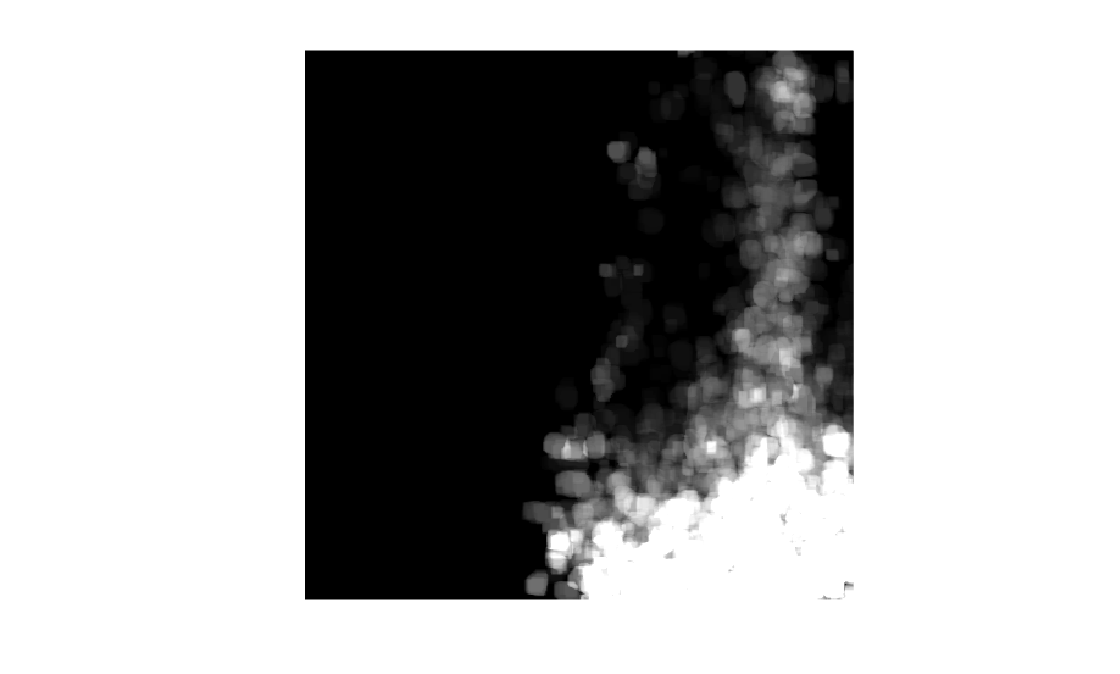

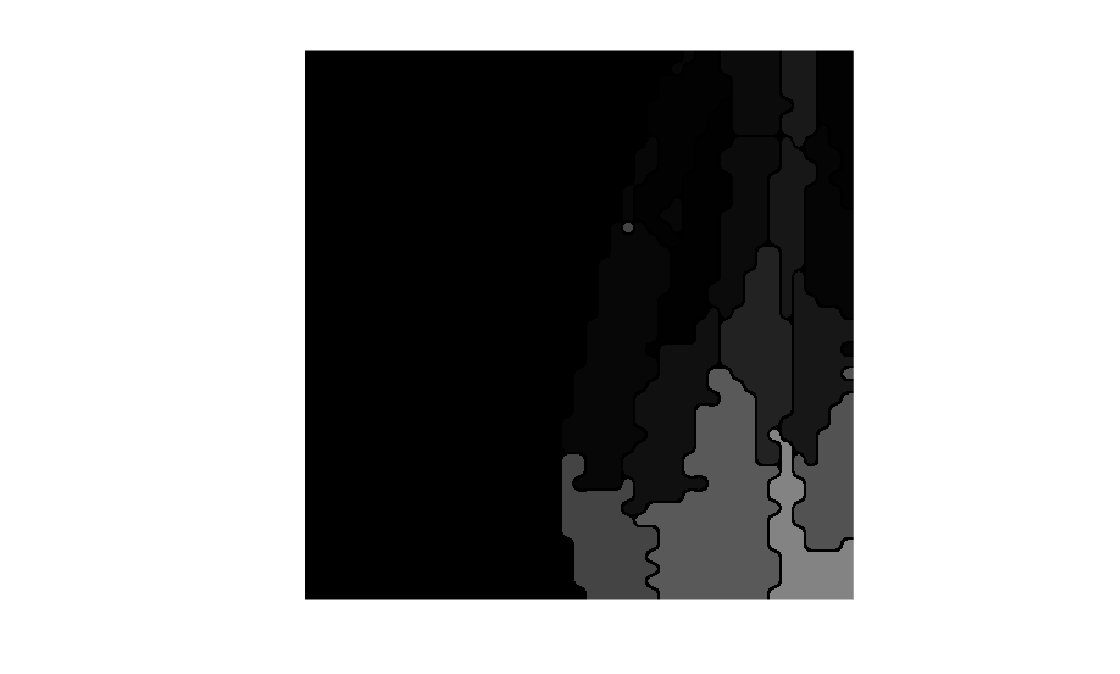

% high contrast sp5l map overlay
to_display = 1;
f3 = figure;
for sn = to_display
    f1 = figure;
    f2 = figure;

    signal_map = squeeze(atlas_signals(:, :, sn));
    signal_map = signal_map(TRUNC_ROW_START:TRUNC_ROW_END, 1:size(signal_map, 2)/2);
    mean_map = 0*signal_map;
    outline_map = 0*signal_map;
    for cn = 1:num_clusters    
        temp = 0*cluster_map;
        temp(cluster_map == cn) = 1 ; %mean(signal_spx_map(cluster_map == cn), 'omitnan');
        temp = imresize(logical(temp), 10);
        temp_erode = double(imerode(temp, strel('square', 3)));

        outline_map((temp - temp_erode) == 1) = 1; %overlay_map(temp_erode == 1) + signal_map(temp_erode == 0);


        temp_erode(temp_erode == 1) = nonzeros(mean(signal_map(temp_erode == 1)));
        mean_map = mean_map + temp_erode; %cat(3, temp_erode + outline_map, 0*temp_erode + outline_map, temp_erode + outline_map);
    end
    figure(f3); imshow(outline_map);
    %signal_map(outline_map == 1) = 1;
    figure(f1); 
    signal_lims = [0 0.3];
    imshow(mat2gray(signal_map, signal_lims));
    %imshow(cat(3, mat2gray(signal_map, signal_lims), outline_map, mat2gray(signal_map, signal_lims)))
    %title(signal_ids{sn});

    figure(f2);
    imshow(mean_map)
    %title(signal_ids{sn});
    saveas(f1, fullfile(plot_dir, ['cluster_overlay_on_signals_lowcontrast', num2str(sn), '.jpg']));
    saveas(f2, fullfile(plot_dir, ['mean_signal_per_cluster_lowcontrals', num2str(sn), '.jpg']));
end

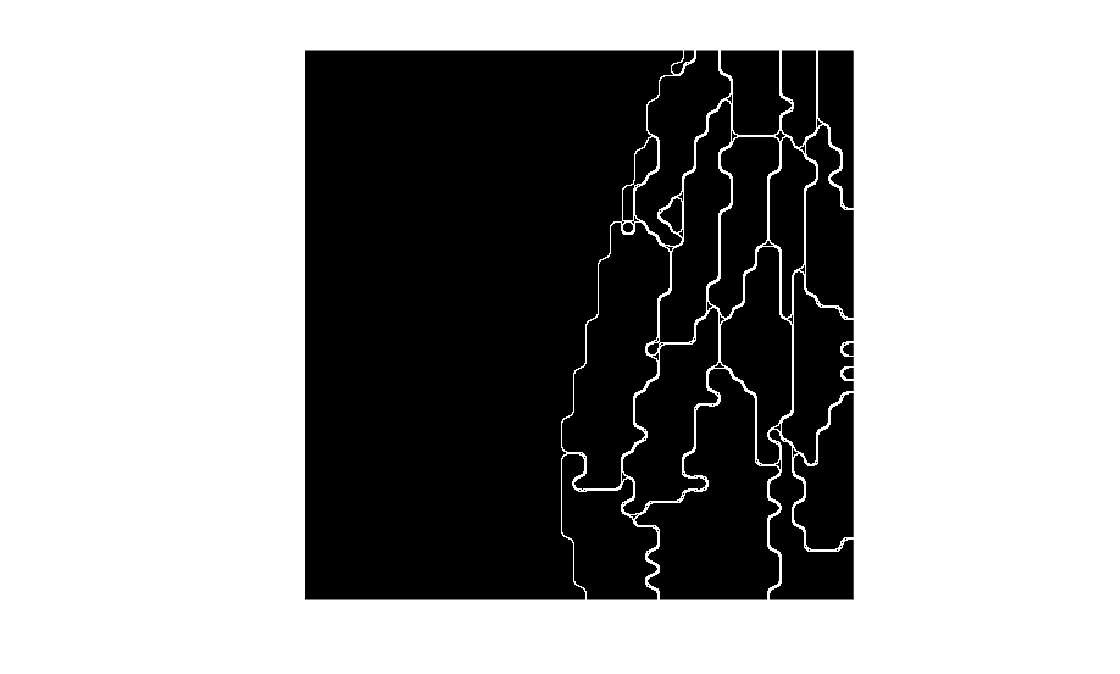

saveas(f3, fullfile(plot_dir, 'cluster_outline_map.jpg'));

## TF-signaling states correlation

% load signaling states 
% signaling states saved from signaling_states_analysis.mlx
if ~isfile('signaling_states_data.mat')
    display("Signaling states data required. Run Figure2_signaling_states_analyis.mlx first.")
else
    var = load('signaling_states_data.mat');
end
signaling_states = var.signaling_states;
sig_spx_pos = signaling_states.spx_pos;
sig_cluster_ids = signaling_states.cluster_ids;
sig_cluster_colors = signaling_states.sig_cluster_colors;
num_sig_states = length(unique(sig_cluster_ids))

num_sig_states = 9

% calculates probability of TF states withing each signaling state
tf_v_sig_overlap = zeros(length(cluster_labels), max(sig_cluster_ids));
sig_state_size = zeros(1, max(sig_cluster_ids));
for tf_state = 1:length(cluster_labels)
    tf_state_elems = spx_pos(clusterIdentifiers == tf_state - 1, :);
    tf_state_idx = sub2ind(size(spx_map), tf_state_elems(:, 1), tf_state_elems(:, 2));
    for sig_state = 1:max(sig_cluster_ids)

        sig_state_elems = sig_spx_pos(sig_cluster_ids == sig_state, :);
        sig_state_idx = sub2ind(size(spx_map), sig_state_elems(:, 1), sig_state_elems(:, 2));

        sig_state_size(sig_state) = length(sig_state_idx);
        
        % IOU
        %tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/length(union(tf_state_idx, sig_state_idx));

        % Fractional distribution across signaling states
        tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/length(sig_state_idx);

        % joint probability
        % tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/size(sig_spx_pos, 1);
    end
end


%figure;
%imagesc(tf_v_sig_overlap)

% get row, col order
rng('default');
row_dist = pdist(tf_v_sig_overlap);
row_links = linkage(row_dist);
f = figure;
[~, ~, dist_row_order] = dendrogram(row_links);
close(f)
rng('default');
col_dist = pdist(tf_v_sig_overlap');
col_links = linkage(col_dist);
f = figure;
[~, ~, col_order] = dendrogram(col_links);
close(f)

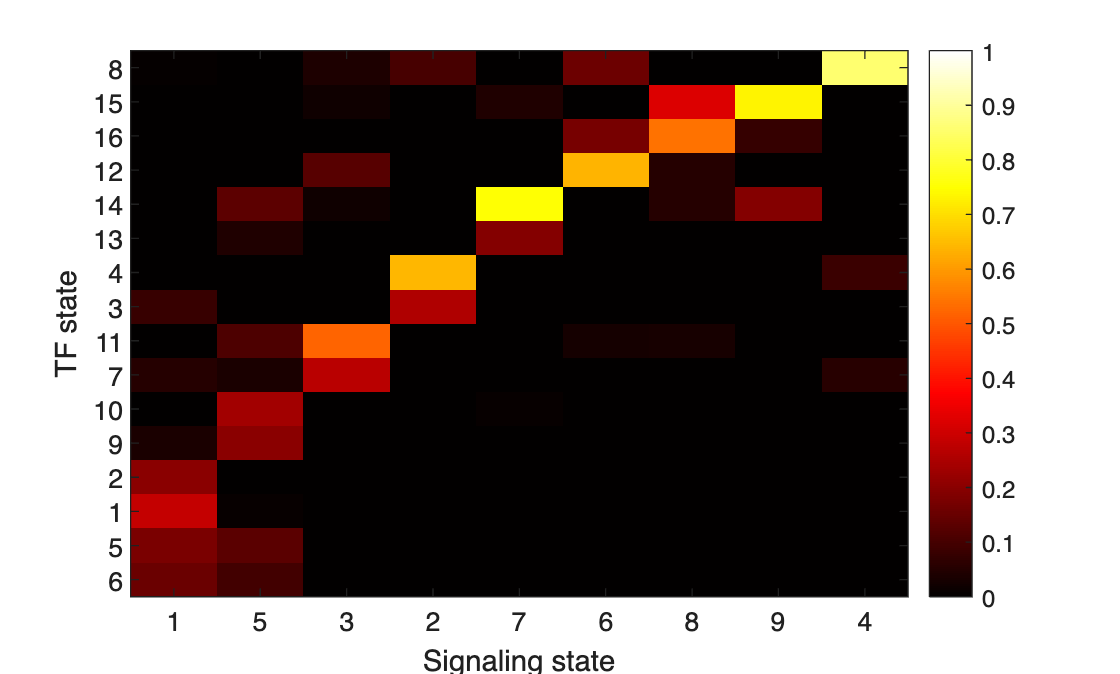

%[~, row_order] = sort(max(tf_v_sig_overlap, [], 2));
row_reorder = [1, 2, 3, 4, 5, 6, 9, 10, 8, 11, 7, 12, 14, 13, 15, 16];
row_order = dist_row_order(row_reorder);

f = figure;
num_rows = size(tf_v_sig_overlap, 1);
num_cols = size(tf_v_sig_overlap, 2);
com = zeros(1, num_cols);
for col = 1:num_cols
    temp = 0*tf_v_sig_overlap;
    [sorted_vals, sort_order] = sort(tf_v_sig_overlap(row_order, col), 'descend');

    com(1, col) = mean(sort_order(1:4).*sorted_vals(1:4));
    %com(1 ,col) = mean((1:num_rows)'.*temp(row_order, col));
end

[~, man_col_order] = sort(com);
%man_col_order = [3, 1, 5, 8, 6, 7, 2, 4];
colormap("hot")
imagesc(tf_v_sig_overlap(row_order(end:-1:1), man_col_order), [0 1]);

row_labels = 1:16;
yticks(row_labels);
[~, apml_labels] = ismember(row_labels, reshape(transpose(new_label_grid), [], 16));
%(row_order(end:-1:1)); %original TF cluster labels
yticklabels(apml_labels(row_order(end:-1:1)));
ylabel('TF state')

col_labels = 1:num_sig_states;
xticks(col_labels)
xticklabels(col_labels(man_col_order))
xlabel('Signaling state')
colorbar()
saveas(f, fullfile(plot_dir, 'TF_v_sig_state_apml_TFlabels.svg'))

## Calculate mutual information between signaling and TFs

joint_TF_v_sig_P_matrix = bsxfun(@times, tf_v_sig_overlap, sig_state_size/sum(sig_state_size));
I = mutual_information(joint_TF_v_sig_P_matrix)

I = 1.7805

##  Shift signaling boundaries

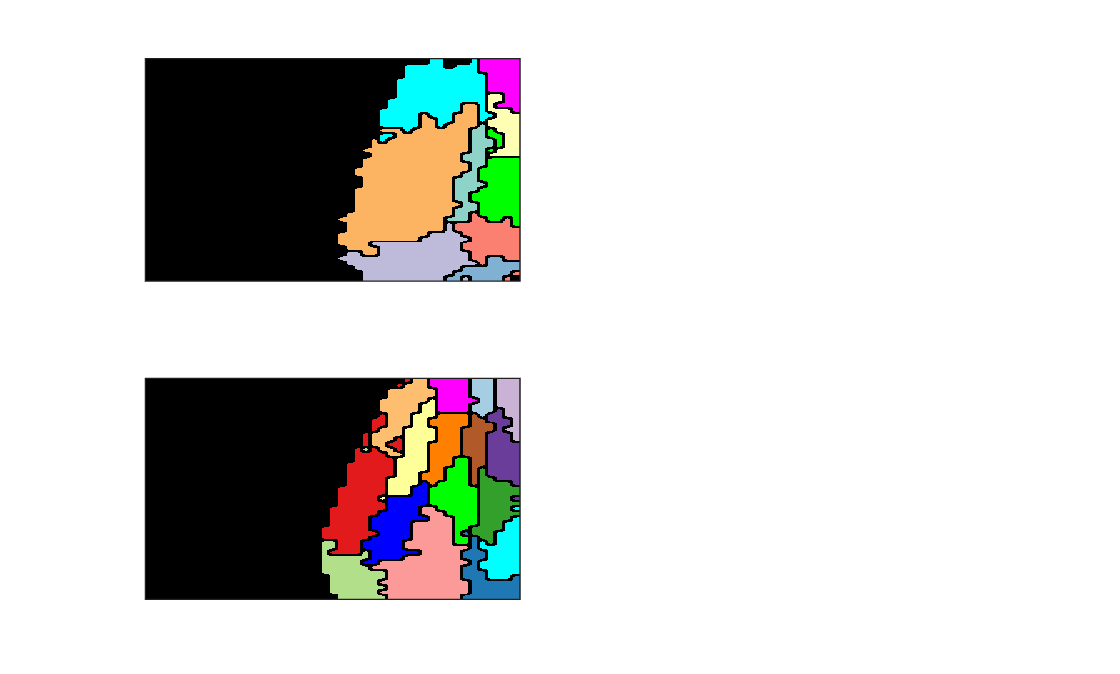

TF_v_sig_plot_dir = fullfile(plot_dir, 'TF_v_sig');
if ~exist(TF_v_sig_plot_dir, 'dir')
    mkdir(TF_v_sig_plot_dir)
end

% sig_cluster_colors = cbrewer2('Set3', 6);
% sig_cluster_colors = cat(1, sig_cluster_colors, [0 1 1; 1 0 1; 0 1 0; 0 0 1]);

f1 = figure;
sig_cluster_map = zeros(size(spx_map));
sig_cluster_map_rgb = repmat(0*spx_map, 1, 1, 3);
sig_cluster_labels = unique(sig_cluster_ids);

for p = 1:size(sig_spx_pos, 1)
    px_color = sig_cluster_colors(find(sig_cluster_labels == sig_cluster_ids(p)), :);
    sig_cluster_map(sig_spx_pos(p, 1), sig_spx_pos(p, 2)) = sig_cluster_ids(p);
    sig_cluster_map_rgb(sig_spx_pos(p, 1), sig_spx_pos(p, 2), :) = px_color; 
end

outlined_sig_cluster_map_rgb =  zeros(5*size(sig_cluster_map, 1), 5*size(sig_cluster_map, 2), 3); %0*cluster_map_rgb; %
for cn = 1:num_sig_states
    temp = 0*sig_cluster_map;
    temp(sig_cluster_map == cn) = 1;
    temp = imresize(logical(temp), 5);
    temp_erode = imerode(temp, strel('square', 3));
    %temp_erode = temp - temp_erode; %imerode(temp_erode, strel('square', 3));
    cc = sig_cluster_colors(cn, :);
    outlined_sig_cluster_map_rgb = outlined_sig_cluster_map_rgb + cat(3, cc(1)*temp_erode, cc(2)*temp_erode, cc(3)*temp_erode);
end
            
f1 = figure;
subplot(2, 2, 1); 
imagesc(outlined_sig_cluster_map_rgb);
xticks(''); yticks('');

subplot(2, 2, 3);   
imagesc(outlined_cluster_map_rgb);
xticks(''); yticks('');

%saveas(f1, fullfile(TF_v_sig_plot_dir, 'original_signaling_state_map.svg'));

np_mask = logical(sig_cluster_map);


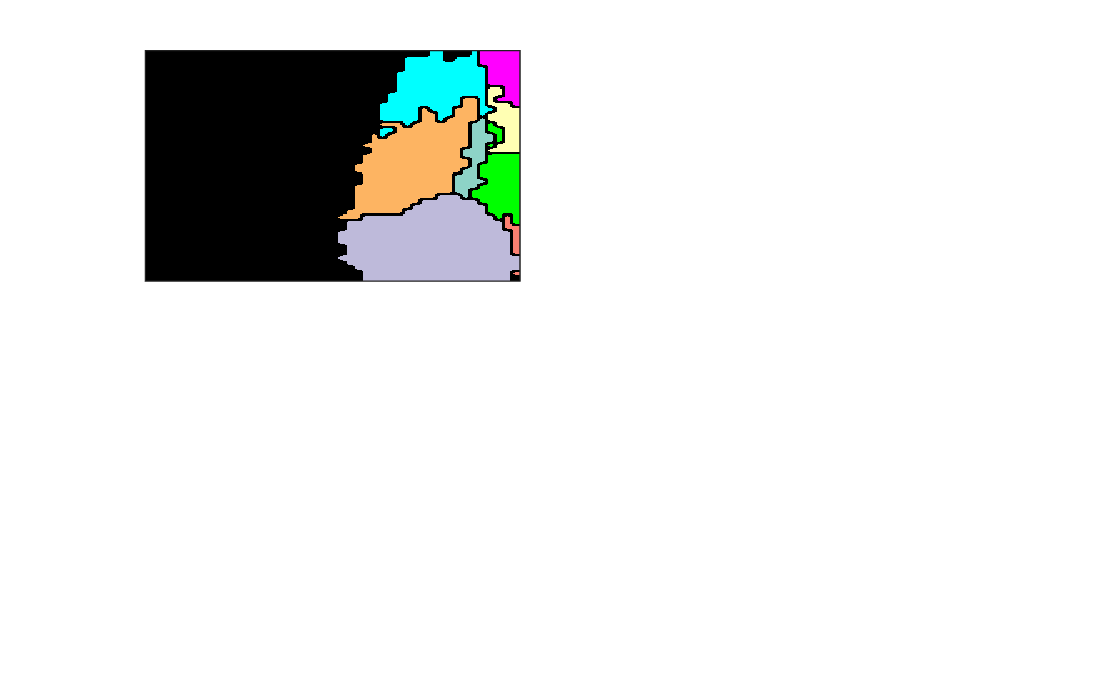

domain_range = 1:size(tf_v_sig_overlap, 2);
scale_range = [1, 1.5, 2, 2.5, 3, 3.5, 4, 4.5, 5];
relative_domain_sizes = [];
starting_sizes = histcounts(sig_cluster_ids);
MI_vals = [];
i = 1;
for cn = domain_range
    target_cn = cn;
    for target_scale = scale_range

        shifted_cluster_ids = scale_domain(sig_cluster_map, np_mask, sig_spx_pos, sig_cluster_ids, target_cn, target_scale);
        
        % tabulate relative area changes
        relative_domain_sizes(end + 1, :) = abs(histcounts(shifted_cluster_ids, 1:(length(starting_sizes) + 1)) - starting_sizes)./starting_sizes;

        shifted_tf_v_sig_overlap = zeros(length(cluster_labels), length(starting_sizes));
        shifted_state_size = zeros(1, max(sig_cluster_ids));
        for tf_state = 1:length(cluster_labels)
            tf_state_elems = spx_pos(clusterIdentifiers == tf_state - 1, :);
            tf_state_idx = sub2ind(size(spx_map), tf_state_elems(:, 1), tf_state_elems(:, 2));
            for sig_state = 1:max(shifted_cluster_ids)
        
                sig_state_elems = sig_spx_pos(shifted_cluster_ids == sig_state, :);
                sig_state_idx = sub2ind(size(spx_map), sig_state_elems(:, 1), sig_state_elems(:, 2));
                shifted_state_size(sig_state) = length(sig_state_idx);
                % Fractional distribution across signaling states
                shifted_tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/length(sig_state_idx);

                % shifted_tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/size(sig_spx_pos, 1);
            end
        end

%         figure;
%         colormap("hot")
%         imagesc(shifted_tf_v_sig_overlap(row_order, man_col_order(end:-1:1)), [0 0.5]);
%         colorbar()
% 
%         row_labels = 1:16;
%         yticks(row_labels)
%         yticklabels(row_labels(row_order))
%         col_labels = 1:6;
%         xticks(col_labels)
%         xticklabels(col_labels(man_col_order(end:-1:1)))

        shifted_joint_tf_v_sig_P_matrix = bsxfun(@times, shifted_tf_v_sig_overlap, shifted_state_size/sum(shifted_state_size));
        I = mutual_information(shifted_joint_tf_v_sig_P_matrix);
        MI_vals(end + 1) = I;

        if cn == 7 && target_scale == 3
            f1 = figure;
            shifted_cluster_map_rgb = repmat(0*spx_map, 1, 1, 3);
            shifted_cluster_map = zeros(size(spx_map));

            for p = 1:size(sig_spx_pos, 1)
                px_color = sig_cluster_colors(find(sig_cluster_labels == shifted_cluster_ids(p)), :);
                shifted_cluster_map(sig_spx_pos(p, 1), sig_spx_pos(p, 2)) = shifted_cluster_ids(p); 
                shifted_cluster_map_rgb(sig_spx_pos(p, 1), sig_spx_pos(p, 2), :) = px_color; 
            end
    
            outlined_shifted_cluster_map_rgb =  zeros(5*size(shifted_cluster_map, 1), 5*size(shifted_cluster_map, 2), 3); %0*cluster_map_rgb; %
            for cn = 1:num_sig_states
                temp = 0*sig_cluster_map;
                if ~isempty(find(shifted_cluster_map == cn, 1, 'first'))
                    temp(shifted_cluster_map == cn) = 1;
                    temp = imresize(logical(temp), 5);
                    temp_erode = imerode(temp, strel('square', 3));
                    %temp_erode = temp - temp_erode; %imerode(temp_erode, strel('square', 3));
                    cc = sig_cluster_colors(cn, :);
                    outlined_shifted_cluster_map_rgb = outlined_shifted_cluster_map_rgb + cat(3, cc(1)*temp_erode, cc(2)*temp_erode, cc(3)*temp_erode);
                end
            end

            subplot(2, 2, 1); 
            imagesc(outlined_shifted_cluster_map_rgb);
            xticks(''); yticks('');
            plot_i = i;
            saveas(f1, fullfile(TF_v_sig_plot_dir, ['signaling_state_expandcontract_state_', num2str(cn), '_scaled_', num2str(target_scale), '.svg']));
        end
        i = i + 1;
    end
end

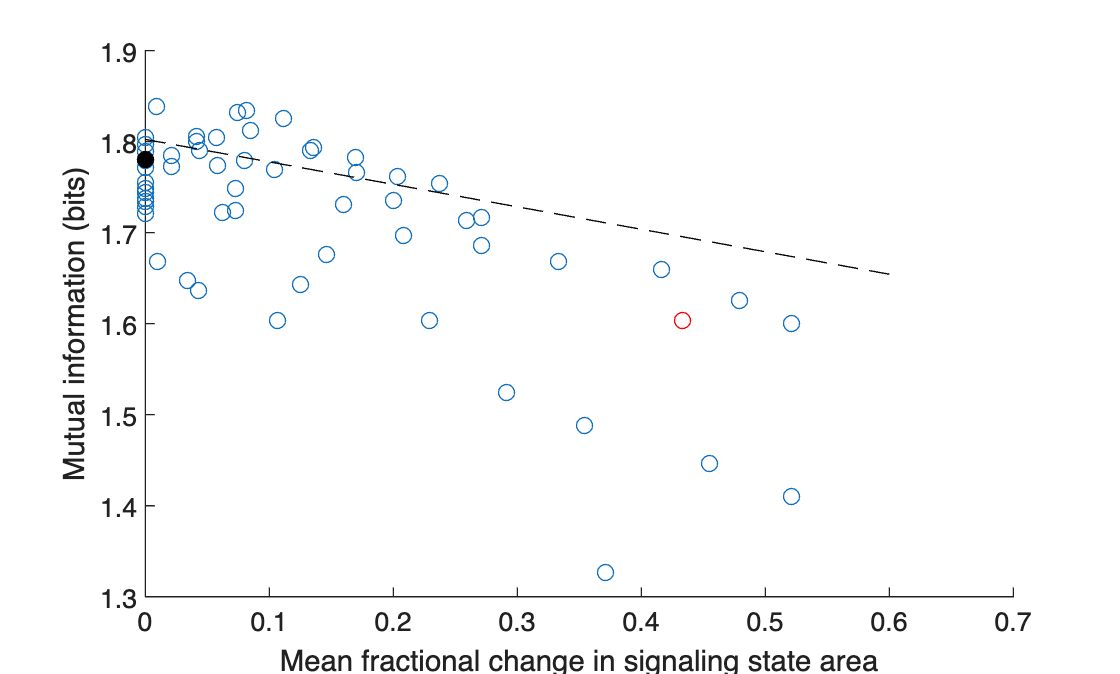

plot_idx = find(MI_vals);

f1 = figure; hold on;
plot(median(relative_domain_sizes(plot_idx, :), 2), MI_vals(plot_idx ), 'o')
plot(mean(relative_domain_sizes(plot_i, :), 2), MI_vals(plot_i), 'ro')
plot(mean(relative_domain_sizes(1, :), 2), MI_vals(1), 'ko', 'MarkerFaceColor', 'black')
ft = fit(mean(relative_domain_sizes(plot_idx, :), 2), MI_vals(plot_idx)', 'poly1');
lims = xlim;
plot([lims(1) lims(2)], [lims(1) lims(2)]*ft.p1 + ft.p2, 'k--')
xlabel('Mean fractional change in signaling state area')
ylabel('Mutual information (bits)')
saveas(f1, fullfile(TF_v_sig_plot_dir, 'domain_size_vs_MI.svg'))

% figure; 
% subplot(2, 2, 1)
% [spx_pos_r, spx_pos_c, shifted_cluster_ids] = shift_boundaries(sig_cluster_map, np_mask)
% subplot(2, 2, 2)
% imagesc(sig_cluster_map)

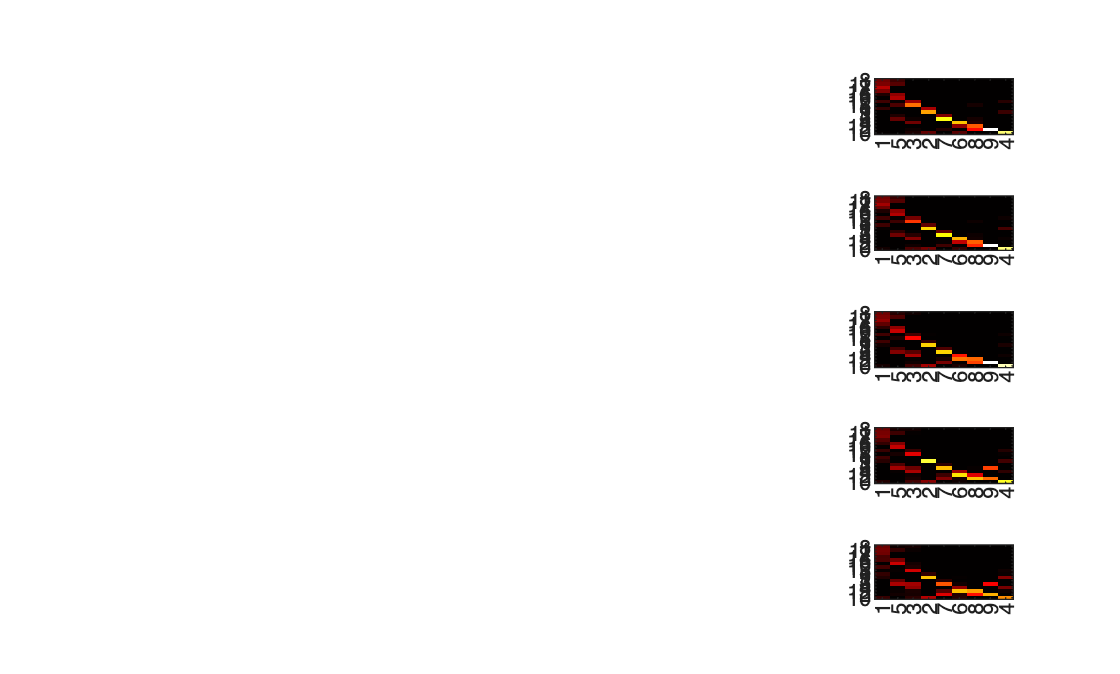

% Measure effect of shifts in boundaries 
f1 = figure; f2 = figure;
scale_range = [0, 1, 2, 3, 4];
relative_domain_sizes = [];
starting_sizes = histcounts(sig_cluster_ids);
nnzs = [];
MI_vals = [];
num_iter = 5;


i = 1;
for target_shift = scale_range
    cum_shifted_tf_v_sig_overlap = zeros(length(cluster_labels), max(sig_cluster_ids));
    for iter = 1:num_iter    
        figure(f1)
        subplot(num_iter, length(scale_range), i)
        shifted_boundary_map = shift_boundaries(sig_cluster_map, np_mask, target_shift, sig_cluster_colors);
        [spx_pos_r, spx_pos_c, shifted_cluster_ids] = find(shifted_boundary_map);

        shifted_cluster_map_rgb = 0*repmat(shifted_boundary_map, 1, 1, 3);
        for p = 1:size(spx_pos_r, 1)
            px_color = sig_cluster_colors(find(sig_cluster_labels == shifted_cluster_ids(p)), :);
            %shifted_cluster_map(sig_spx_pos(p, 1), sig_spx_pos(p, 2)) = shifted_cluster_ids(p);
            shifted_cluster_map_rgb(sig_spx_pos(p, 1), sig_spx_pos(p, 2), :) = px_color;
        end
        
        imagesc(shifted_cluster_map_rgb);
        xticks(''); yticks('')
        shifted_spx_pos = cat(2, spx_pos_r, spx_pos_c);
        
        % tabulate relative area changes
        relative_domain_sizes(end + 1, :) = histcounts(shifted_cluster_ids, 1:(length(starting_sizes) + 1))./starting_sizes;

        % missing signaling domains
        missing_idx = find(relative_domain_sizes(end, :) == 0);
        for missing = missing_idx
            shifted_cluster_ids(find(sig_cluster_ids == missing, 1, 'first')) = missing;
        end

        shifted_tf_v_sig_overlap = zeros(length(cluster_labels), max(shifted_cluster_ids));
        shifted_state_size = zeros(1, max(sig_cluster_ids));
        for tf_state = 1:length(cluster_labels)
            tf_state_elems = spx_pos(clusterIdentifiers == tf_state - 1, :);
            tf_state_idx = sub2ind(size(spx_map), tf_state_elems(:, 1), tf_state_elems(:, 2));
            for sig_state = 1:length(starting_sizes)
        
                sig_state_elems = shifted_spx_pos(shifted_cluster_ids == sig_state, :);
                sig_state_idx = sub2ind(size(spx_map), sig_state_elems(:, 1), sig_state_elems(:, 2));
                shifted_state_size(sig_state) = length(sig_state_idx);
                % Fractional distribution across signaling states
                shifted_tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/length(sig_state_idx);
    
                % shifted_tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/size(sig_spx_pos, 1);
            end
        end

        cum_shifted_tf_v_sig_overlap = cum_shifted_tf_v_sig_overlap + shifted_tf_v_sig_overlap;
        if iter == num_iter 
            figure(f2);
            subplot(num_iter, length(scale_range), i)
            colormap("hot")
            imagesc(cum_shifted_tf_v_sig_overlap(row_order, man_col_order)/num_iter, [0 1]);
            %colorbar()

            row_labels = 1:16;
            yticks(row_labels)
            yticklabels(row_labels(row_order))
            col_labels = 1:num_sig_states;
            xticks(col_labels)
            xticklabels(col_labels(man_col_order))
        end
    
        shifted_joint_tf_v_sig_P_matrix = bsxfun(@times, shifted_tf_v_sig_overlap, shifted_state_size/sum(shifted_state_size));
        nnzs(end + 1) = length(nonzeros(shifted_joint_tf_v_sig_P_matrix));
        I = mutual_information(shifted_joint_tf_v_sig_P_matrix);
        MI_vals(end + 1) = I;
        i = i + 1;



    end
end

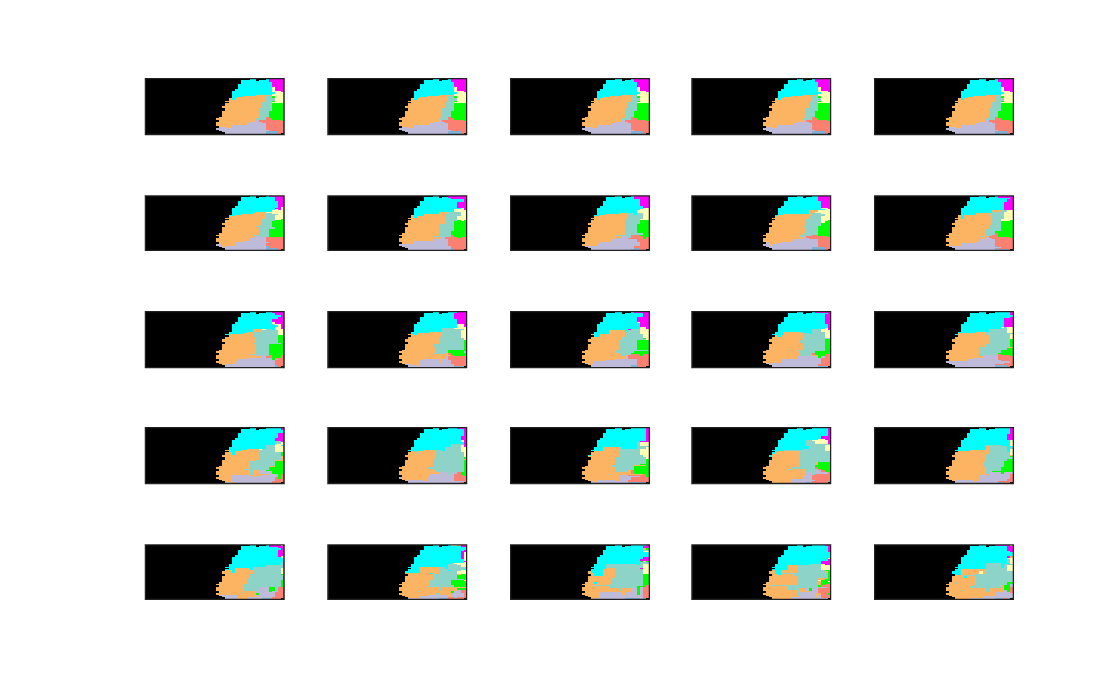

saveas(f1, fullfile(TF_v_sig_plot_dir, 'boundary_shift_maps_alliterations.svg'))

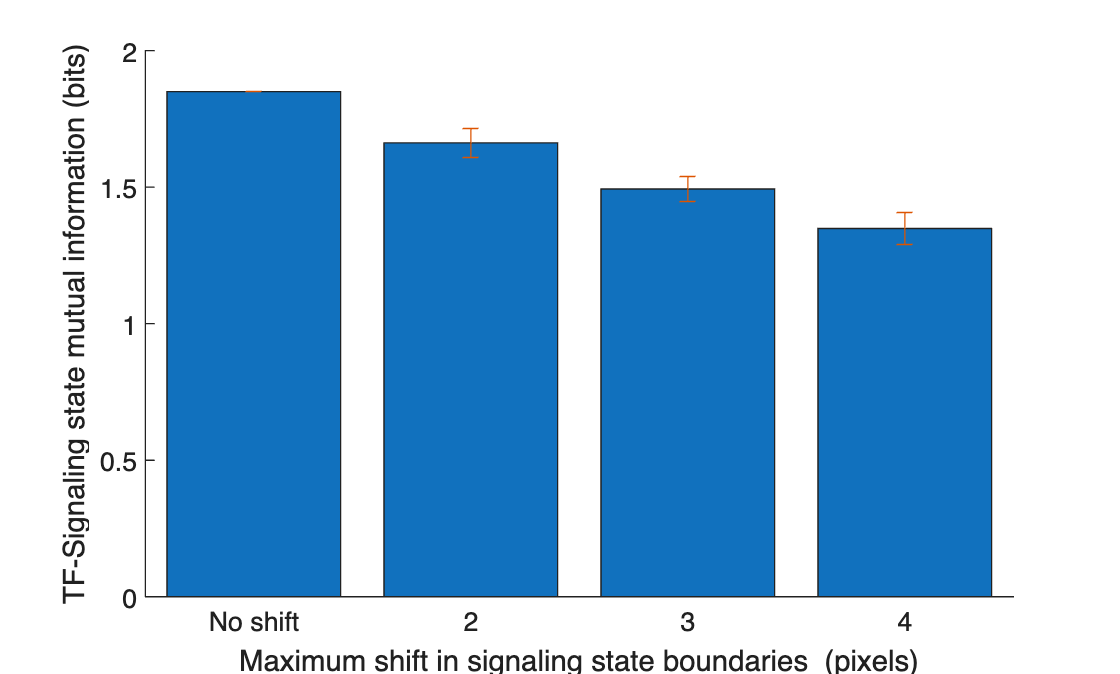

MI_vals = reshape(MI_vals, [num_iter, length(scale_range)]);
MI_vals(MI_vals == 0) = nan;
median_MI_vals = median(MI_vals, 1, 'omitnan');
std_MI_vals = std(MI_vals, [], 1, 'omitnan');
plot_idx = [1, 3, 4, 5];
f1 = figure; hold on;
ax = gca;
bar(ax, median_MI_vals(plot_idx))
errorbar(ax, 1:size(MI_vals(plot_idx, :), 1), median_MI_vals(plot_idx), std_MI_vals(plot_idx), 'LineStyle', 'none')
ylabel('TF-Signaling state mutual information (bits)');
xlim([0.5 4.5])
xticks(1:4)
xticklabels({'No shift', num2str(scale_range((plot_idx(2)))), num2str(scale_range((plot_idx(3)))), num2str(scale_range((plot_idx(4))))})
xlabel('Maximum shift in signaling state boundaries  (pixels)');
saveas(f1, fullfile(TF_v_sig_plot_dir, 'boundary_shift_MI_barplot.svg'))

boundary_shift_MI_barplot_pvals = zeros(1, length(plot_idx));
% P-value for mean of shift  MIs
for pval_id = 2:length(plot_idx)
    mu = mean(MI_vals(:, plot_idx(pval_id)), 'omitnan');
    sigma = std(MI_vals(:, plot_idx(pval_id)), 'omitnan');
    z = (mean(MI_vals(:, plot_idx(1))) - mu)/sigma;
    p = 1 - normcdf(z)
    boundary_shift_MI_barplot_pvals(pval_id) = p;
end

p = 7.3564e-05

p = 1.4433e-15

p = 0

save('boundary_shift_MI_barplot_pvals.mat', 'boundary_shift_MI_barplot_pvals')
%reshape(nnzs, [length(scale_range), num_iter])
%length(nonzeros(joint_TF_v_sig_P_matrix))

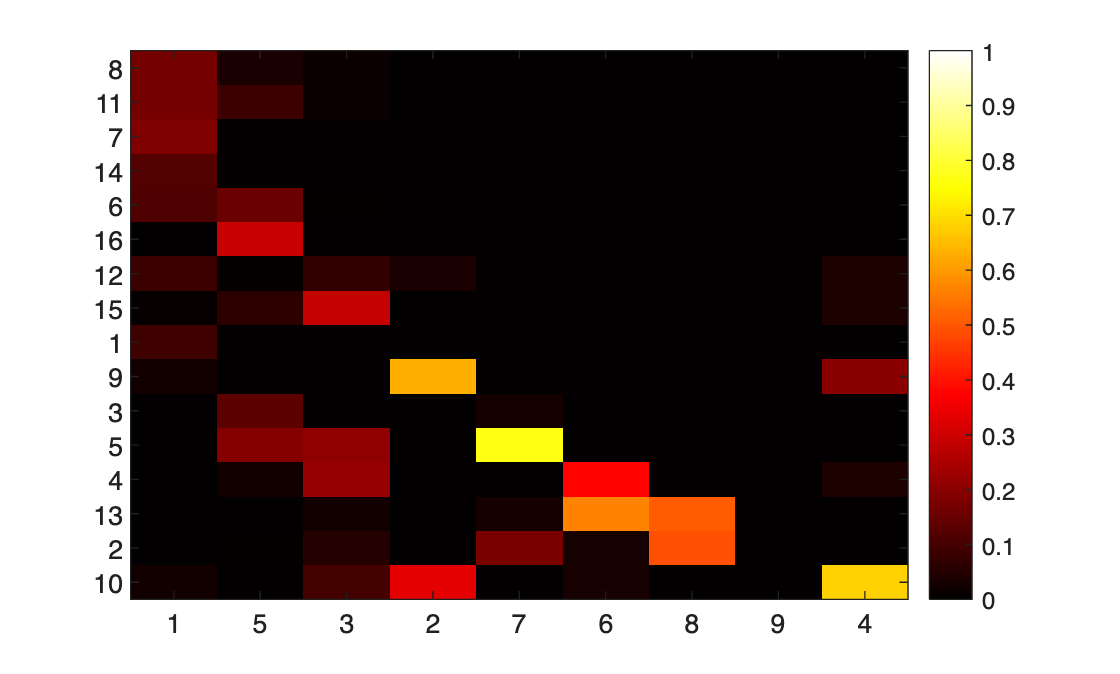

shifted_tf_v_sig_overlap = zeros(length(cluster_labels), max(shifted_cluster_ids));
shifted_state_size = zeros(1, max(sig_cluster_ids));
target_shift = plot_idx(2);
shifted_boundary_map = shift_boundaries(sig_cluster_map, np_mask, target_shift, sig_cluster_colors);
[spx_pos_r, spx_pos_c, shifted_cluster_ids] = find(shifted_boundary_map);

for tf_state = 1:length(cluster_labels)
    tf_state_elems = spx_pos(clusterIdentifiers == tf_state - 1, :);
    tf_state_idx = sub2ind(size(spx_map), tf_state_elems(:, 1), tf_state_elems(:, 2));
    for sig_state = 1:max(shifted_cluster_ids)

        sig_state_elems = sig_spx_pos(shifted_cluster_ids == sig_state, :);
        sig_state_idx = sub2ind(size(spx_map), sig_state_elems(:, 1), sig_state_elems(:, 2));
        shifted_state_size(sig_state) = length(sig_state_idx);
        % Fractional distribution across signaling states
        shifted_tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/length(sig_state_idx);

        %shifted_tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/size(sig_spx_pos, 1);
    end
end

figure;
colormap("hot")
imagesc(shifted_tf_v_sig_overlap(row_order, man_col_order), [0 1]);
colorbar()

row_labels = 1:16;
yticks(row_labels)
yticklabels(row_labels(row_order))
col_labels = 1:num_sig_states;
xticks(col_labels)
xticklabels(col_labels(man_col_order))

## Ptch2 only

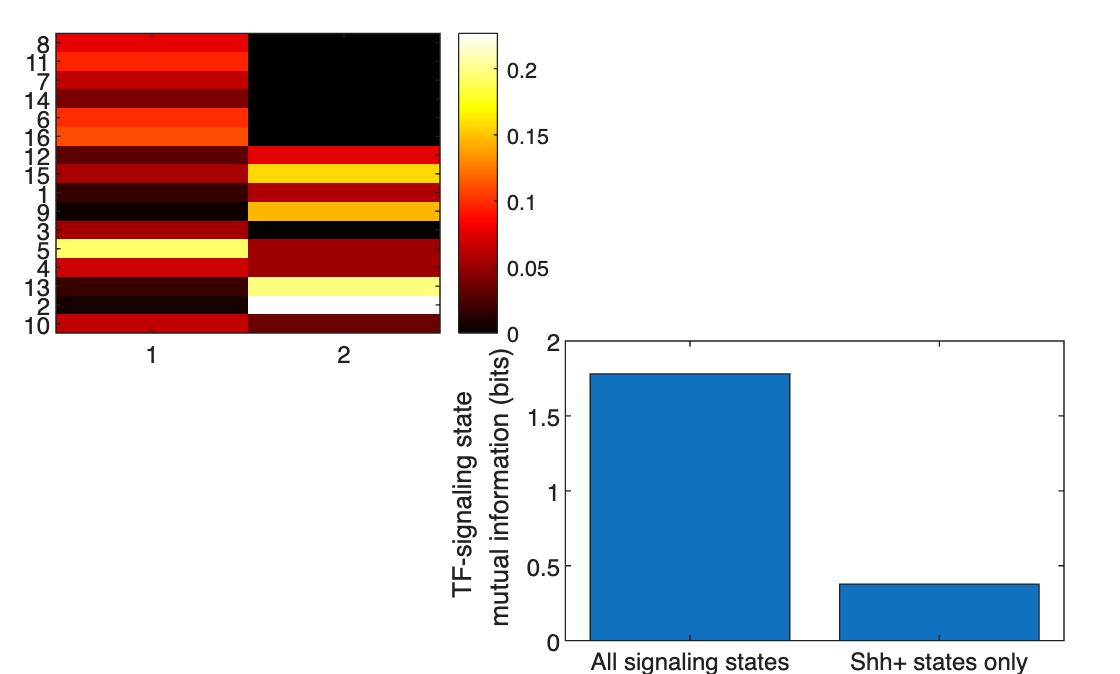

shh_signaling_states = [2, 3, 64, 8, 9];
shh_cluster_ids = ones(size(sig_cluster_ids));
shh_cluster_ids(ismember(sig_cluster_ids, shh_signaling_states)) = 2;

shh_tf_v_sig_overlap = zeros(length(cluster_labels), max(shh_cluster_ids));
shh_state_size = zeros(1, max(shh_cluster_ids));
for tf_state = 1:length(cluster_labels)
    tf_state_elems = spx_pos(clusterIdentifiers == tf_state - 1, :);
    tf_state_idx = sub2ind(size(spx_map), tf_state_elems(:, 1), tf_state_elems(:, 2));
    for sig_state = 1:max(shh_cluster_ids)

        sig_state_elems = sig_spx_pos(shh_cluster_ids == sig_state, :);
        sig_state_idx = sub2ind(size(spx_map), sig_state_elems(:, 1), sig_state_elems(:, 2));
        shh_state_size(sig_state) = length(sig_state_idx);
        % Fractional distribution across signaling states
        shh_tf_v_sig_overlap(tf_state, sig_state) = length(intersect(tf_state_idx, sig_state_idx))/length(sig_state_idx);
    end
end

f1 = figure;
colormap("hot")
subtightplot(2, 2, 1);
imagesc(shh_tf_v_sig_overlap(row_order, :));
xticks(1:2)
xticklabels({'Shh-', 'Shh+'})
colorbar();

row_labels = 1:16;
yticks(row_labels)
yticklabels(row_labels(row_order))
col_labels = 1:2;
xticks(col_labels)
xticklabels(col_labels)

joint_shh_TF_v_sig_P_matrix = bsxfun(@times, shh_tf_v_sig_overlap, shh_state_size/sum(shh_state_size));

joint_TF_v_sig_P_matrix = bsxfun(@times, tf_v_sig_overlap, sig_state_size/sum(sig_state_size));
subtightplot(2, 2, 4)
bar([mutual_information(joint_TF_v_sig_P_matrix), mutual_information(joint_shh_TF_v_sig_P_matrix)])
xlim([0.5 2.5])
xticks(1:2);
xticklabels({'All signaling states', 'Shh+ states only'});
ylabel('TF-signaling state \newline mutual information (bits)');
saveas(f1, fullfile(TF_v_sig_plot_dir, 'Shh_MI_comparison.svg'))

function shifted_cluster_ids = scale_domain(sig_cluster_map, np_mask, sig_spx_pos, sig_cluster_ids, target_cn, target_scale)
    roi_map = 0*sig_cluster_map;
    roi_map(sig_cluster_map == target_cn) = 1;
    
    targetArea = nnz(roi_map) * target_scale;
    
    % Distance from the region outward
    D = bwdist(roi_map);   % distance to nearest foreground pixel
    
    % Sort all candidate pixels by distance
    [d_sorted, idx] = sort(D(:), 'ascend');
    
    roi_expanded = roi_map;
    currentArea = nnz(roi_map);
    
    i = 1;
    while currentArea < targetArea && i <= numel(idx)
        if ~roi_expanded(idx(i))
            roi_expanded(idx(i)) = true;
            currentArea = currentArea + 1;
        end
        i = i + 1;
    end
    
    masked_diff_map = (roi_expanded - roi_map).*np_mask;
    [i, j, v] = find(masked_diff_map);
    shifted_cluster_ids = sig_cluster_ids;
    shifted_cluster_ids(find(ismember(sig_spx_pos, [i, j], 'rows'))) = target_cn;
end

function shifted_boundary_map = shift_boundaries(sig_cluster_map, np_mask, maxShift, sig_cluster_colors)

    labels = (unique(sig_cluster_map));
    labels(labels == 0) = [];   % remove background if present
    [h, w] = size(sig_cluster_map);
    numRegions = numel(labels);

    
    D = zeros(h, w, numRegions);
    
    % Compute distance transform for each region
    for k = 1:numRegions
        BW = (sig_cluster_map == labels(k));
        D(:,:,k) = bwdist(BW);
    end
    
    % Add random perturbation (controls boundary jitter)
    noise = maxShift * randn(size(D));
    
    D_perturbed = D + noise;
    %D_perturbed = D + maxShift*ones(size(D));
    
    % Reassign pixels to closest (perturbed) region
    [~, idx] = min(D_perturbed, [], 3);


    boundaryMask = false(size(sig_cluster_map));

    for k = 1:numRegions
        BW = (sig_cluster_map == labels(k));
        boundaryMask = boundaryMask | bwperim(BW);
    end
    
    boundaryMask = imdilate(boundaryMask, strel('disk', maxShift));
    
    % Only update those pixels
    L_new = sig_cluster_map;
    L_new(boundaryMask) = labels(idx(boundaryMask));

    L_contig = 0*L_new;
    for k = 1:numRegions
        BW = (L_new == labels(k));
        BW = imclose(BW, strel('disk', 3));
        BW(L_contig > 0) = 0;
        L_contig = L_contig + labels(k)*BW;
    end
    shifted_boundary_map = L_contig.*np_mask;


end